clc                     % clear command window
clear                   % clear MATLAB workspace
clf

[robotArduino]= SETUPARDUINO('COM3') 

robotArduino =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Nano33BLE'
         AvailablePins: {'D0-D13', 'A0-A7'}
  AvailableDigitalPins: {'D0-D13', 'A0-A7'}
      AvailablePWMPins: {'D0-D13'}
   AvailableAnalogPins: {'A0-A3', 'A6-A7'}
    AvailableI2CBusIDs: [0, 1]
AvailableSerialPortIDs: [1]
             Libraries: {'I2C', 'Servo'}
Show all properties


steerServo = servo(robotArduino, 'D5', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
driveServo = servo(robotArduino, 'D3', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
panServo = servo(robotArduino, 'D6', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);

writePosition(steerServo, 0.5);      % always start servo-command at 0.5
writePosition(driveServo, 0.3);      % always start servo-command at 0.5
writePosition(panServo, 0.5);        % always start servo-command at 0.5
pause(3.0);                          % wait for Arduino to send stable pwm
warning ('actuators live');

% calibrate to 0.1 - 0.3 - 0.9
writePosition(driveServo, 0.3);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.51);

joy=vrjoystick(1); 
while true
    one = axis(joy, 1)
    two = axis(joy, 2)
    three = axis(joy, 3)
    writePosition(steerServo, -one*0.16 + 0.54)
    writePosition(driveServo, -two*0.02 + 0.35)
    writePosition(panServo, -three*0.5 + 0.5)
    
    pause(0.01)


end

clear lid
lid = LIDAR('COM6')

lid =   LIDAR with properties:

        lidar: [1×1 serial]
     pol_data: []
    cart_data: []


lidar_data = lid.scan(5000);

lid.close()

gps = NEO_M8U_USB('COM4')


gps_data = gps.getBasic();

clear gps 

lidar_data = lid.scan(10000);
left = lidar_data(:, lidar_data(2,:) > 0 & 0 < lidar_data(1,:) < 500);
plot(left(1,:), left(2,:), '*')
right = lidar_data(:, lidar_data(2,:) < 0 & 0 < lidar_data(1,:) < 500);
plot(right(1,:), right(2,:), '*')
    
lefts = sort(abs(sqrt(left(1,:).^2 + left(2,:).^2)));
rights = sort(abs(sqrt(right(1,:).^2 + right(2,:).^2)));

gpsPlot = figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])
hold on;
% plot rover poition, you can change this line to plot roverX and RoverY 
gpsPoint = geoplot(42.2935, -71.264, 'r*')
% Import a satellite photo basemap to draw on
geobasemap satellite
legend('Rover GPS Track')
movegui(gpsRoverPlot,'south');
hold off;


plot(lidar_data(1,:), lidar_data(2,:), '*')

save('4-27-lg-01', "lidar_data")

Wall aviod basic

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    lidar_data = lid.scan(10000);
    writePosition(driveServo, 0.38)
    left = lidar_data(:, lidar_data(2,:) > 10 & 100 < lidar_data(1,:) < 8000);
    
    right = lidar_data(:, lidar_data(2,:) < -10 & 100 < lidar_data(1,:) < 8000);
    

    hold on
    clf
    %plot x coor, y coord, and object identity
    plot(lidar_data(2,:), lidar_data(1,:), '*')

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])
    
    lefts = sort(sqrt(abs(left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(right(1,:).^2) + abs(right(2,:).^2)));

    if isempty(rights)
        rights = [20000; 20000];
    elseif isempty(lefts)
        lefts = [20000; 20000];
    end
    
    if min(lefts) < 6000 & (min(lefts) < min(rights))
        writePosition(steerServo, 0.3*0.16 + 0.52);
        title('left')
    elseif min(rights) < 6000 & (min(rights) < min(lefts))
        writePosition(steerServo, -0.3*0.16 + 0.52);
        title('right')
    else
        writePosition(steerServo, 0.52);
        title('straight')
        rights
    end
    pause(0.6)
end

Wall aviod with gradient match

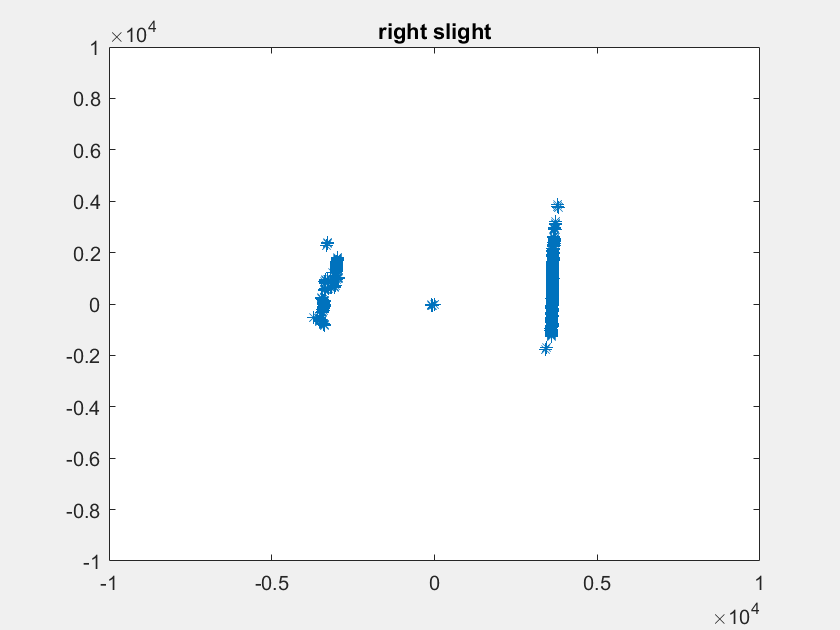

   5.0952e+03



slope = 23.2678

   5.0267e+03



slope = 1.3984

   4.3986e+03



slope = -2.6590

   4.1400e+03



slope = -3.1871

   3.7553e+03



slope = -2.5452

   3.5207e+03



slope = -2.1477

   3.2917e+03



slope = -2.5201

   3.1979e+03



slope = 0.0148

   3.0308e+03



slope = 1.1269

   2.8833e+03



slope = 0.2876

   2.9564e+03



slope = -3.3357

   3.3429e+03



slope = 12.0152

   3.4783e+03



slope = 4.3444

   3.3496e+03



slope = -0.4919

   3.2108e+03



slope = -3.7524

   3.1300e+03



slope = -4.6857

   3.1075e+03



slope = -5.3442

   3.0849e+03



slope = -4.3903

   3.0859e+03



slope = -4.7302

   2.8850e+03



slope = -1.5348

   2.8312e+03



slope = 3.4869

   2.9568e+03



slope = 2.3869

   3.0798e+03



slope = 2.2446

   3.3083e+03



slope = 1.5639

   3.5530e+03



slope = 2.1672

   3.7318e+03



slope = 3.0030

   4.1049e+03



slope = 3.9936

   3.8625e+03



slope = 3.4599

   4.0136e+03



slope = 4.4620

   3.8324e+03



slope = 3.6060

   4.1512e+03



slope = 0.0020

   4.0500e+03



slope = -4.7472

   3.8301e+03



slope = 0.3597

   3.7229e+03



slope = -1.4237

  999.8203



slope = 0.5310

  854.9036



slope = 0.7489

  994.4663



slope = 0.8796

   3.6514e+03



slope = 3.5737

   4.2954e+03



slope = 0.4613

   5.1103e+03



slope = 1.2374

  778.6932



slope = -0.0758

  688.0848



slope = -0.3744

  573.0639



slope = 0.6559

slope = 0

rights =        20000
       20000


  556.9307



slope = -0.2081

slope = 0

rights =        20000
       20000


slope = 0

rights =        20000
       20000


slope = 0

rights =        20000
       20000


slope = 0

rights =        20000
       20000


slope = 0

rights =        20000
       20000


slope = 0

rights =        20000
       20000


slope = 0

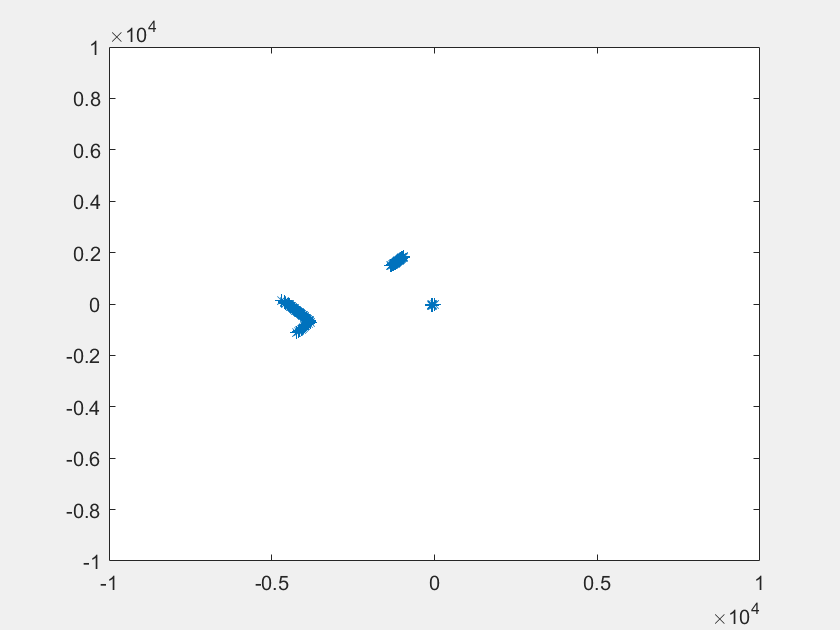

Invalid position value. The value must be between 0 and 1.

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    
    lidar_data = lid.scan(10000);
    writePosition(driveServo, 0.375)
    left = lidar_data(:, lidar_data(1,:) < -300 & 300 < lidar_data(2,:) < 4000);
    
    right = lidar_data(:, lidar_data(1,:) > 300 & 300 < lidar_data(2,:) < 4000);
    
    lefts = sort(sqrt(abs(2.*left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(2.*right(1,:).^2) + abs(right(2,:).^2)));

    disp(min(rights))

    fit = polyfit(right(1,:), right(2,:),1);
    slope = fit(1)
    yfit = fit(1)*rights(1,:)+fit(2);

    if isempty(rights)
        rights = [20000; 20000];
        slope = 0;
    elseif isempty(lefts)
        lefts = [20000; 20000];
    end

    clf

    %plot x coor, y coord, and object identity
    plot(lidar_data(1,:), lidar_data(2,:), '*')
    hold on
    if ~(isempty(rights)) & ~(isempty(yfit))
        plot(rights(1,:), yfit, '--')
    end

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])
    
    if min(lefts) < 3000 & (min(lefts) < min(rights))
        writePosition(steerServo, -(max([300/min(lefts) 0.5])*0.16 + 0.52));
        title('right')
    elseif min(rights) < 3000 & (min(rights) < min(lefts))
        writePosition(steerServo, max([300/min(lefts) 0.5])*0.16 + 0.52);
        title('left')
    elseif slope > 0
        writePosition(steerServo, -0.2*0.16 + 0.52);
        title('right slight')
    elseif slope < 0
        writePosition(steerServo, 0.2*0.16 + 0.52);
        title('left slight')
    else
        writePosition(steerServo, 0.52);
        title('straight')
        rights
    end

    pause(0.5)
end

RANSAC fit

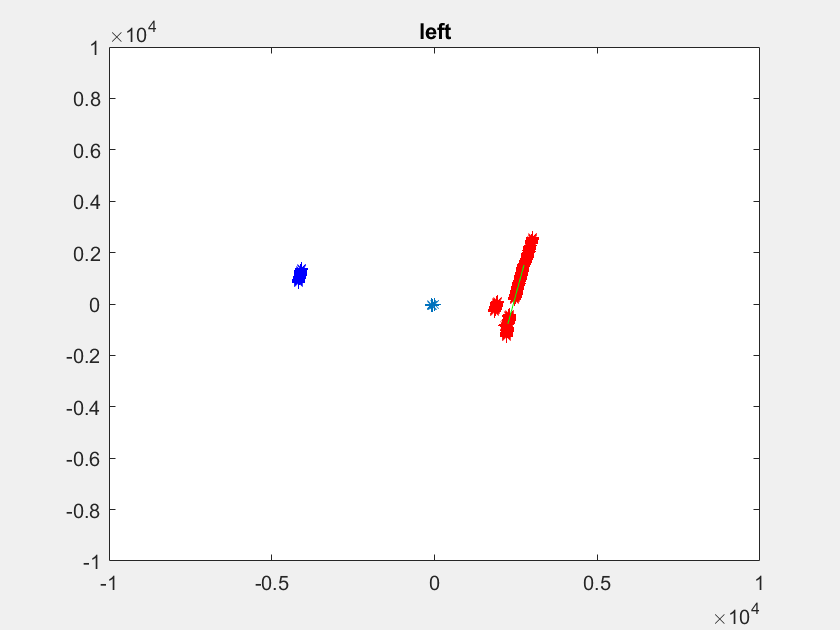

   2.7277e+03



rpoints = 	1.0e+03 *

    1.7987   -1.0385
    1.8025   -1.0259
    1.8087   -1.0149
    1.8132   -1.0028
    1.8193   -0.9916
    1.8042   -0.9691
    1.8093   -0.9575
    1.8107   -0.9440
    1.8164   -0.9329
    1.8186   -0.9199


slope = -1.3619

   2.6175e+03



rpoints = 	1.0e+03 *

    2.2040   -1.2725
    2.1944   -1.2490
    2.2012   -1.2351
    2.2070   -1.2205
    2.2136   -1.2065
    2.2095   -1.1867
    2.2061   -1.1675
    2.2132   -1.1539
    2.2167   -1.1385
    2.2156   -1.1208


slope = 4.6897

   2.5240e+03



rpoints = 	1.0e+03 *

    1.6524   -0.9540
    1.6591   -0.9443
    1.6640   -0.9336
    1.6705   -0.9239
    1.6771   -0.9141
    1.6844   -0.9047
    1.6979   -0.8986
    1.7060   -0.8895
    1.7115   -0.8790
    1.7168   -0.8685


slope = 1.1354

   2.7722e+03



rpoints = 	1.0e+03 *

    1.9607   -1.1320
    1.9676   -1.1199
    1.9744   -1.1078
    1.9803   -1.0952
    1.9870   -1.0830
    1.9936   -1.0708
    1.9966   -1.0567
    2.0031   -1.0444
    2.0095   -1.0320
    1.9801   -1.0016


slope = 2.7117

   2.9472e+03



rpoints = 	1.0e+03 *

    1.9408   -1.1205
    1.9476   -1.1086
    1.9448   -1.0912
    1.9515   -1.0792
    1.9580   -1.0672
    1.9628   -1.0542
    1.9577   -1.0361
    1.9596   -1.0217
    1.9641   -1.0087
    1.9622   -0.9926


slope = 2.4047

   3.6085e+03



rpoints = 	1.0e+03 *

    2.3954   -1.3830
    2.4186   -1.3767
    2.4367   -1.3672
    2.4450   -1.3522
    2.4533   -1.3371
    2.4517   -1.3168
    2.4448   -1.2938
    2.4518   -1.2783
    2.4596   -1.2632
    2.4601   -1.2445


slope = 2.2726

   3.6623e+03



rpoints = 	1.0e+03 *

    2.4050   -1.3885
    2.4134   -1.3737
    2.4218   -1.3589
    2.4240   -1.3406
    2.4173   -1.3175
    2.4209   -1.3003
    2.4288   -1.2854
    2.4482   -1.2765
    2.4453   -1.2559
    2.4637   -1.2463


slope = 1.7287

   4.0559e+03



rpoints = 	1.0e+03 *

    2.6552   -1.5330
    2.6646   -1.5167
    2.6756   -1.5012
    2.6830   -1.4838
    2.6912   -1.4668
    2.7002   -1.4503
    2.7046   -1.4313
    2.7133   -1.4147
    2.7238   -1.3989
    2.7323   -1.3822


slope = 1.5645

   4.1366e+03



rpoints = 	1.0e+03 *

    2.7081   -1.5635
    2.7176   -1.5468
    2.7262   -1.5296
    2.7355   -1.5129
    2.7448   -1.4960
    2.7548   -1.4796
    2.7647   -1.4631
    2.7736   -1.4461
    2.7825   -1.4291
    2.7912   -1.4119


slope = 1.6765

   4.0414e+03



rpoints = 	1.0e+03 *

    2.6457   -1.5275
    2.6550   -1.5112
    2.6643   -1.4949
    2.6690   -1.4761
    2.6780   -1.4597
    2.6887   -1.4441
    2.6975   -1.4276
    2.7063   -1.4110
    2.7149   -1.3943
    2.7207   -1.3763


slope = 2.0879

   4.4268e+03



rpoints = 	1.0e+03 *

    2.9574   -1.4507
    2.9653   -1.4320
    2.9750   -1.4142
    2.9836   -1.3959
    3.0012   -1.3818
    3.0096   -1.3633
    3.0179   -1.3448
    3.0261   -1.3262
    3.0342   -1.3076
    3.0422   -1.2890


slope = 1.8733

   3.8851e+03



rpoints = 	1.0e+03 *

    2.5496   -1.4720
    2.5516   -1.4524
    2.5535   -1.4327
    2.5588   -1.4151
    2.5674   -1.3994
    2.5760   -1.3836
    2.5835   -1.3672
    2.5910   -1.3509
    2.5957   -1.3331
    2.6038   -1.3172


slope = 2.3194

   4.2555e+03



rpoints = 	1.0e+03 *

    2.7877   -1.6095
    2.7915   -1.5889
    2.8012   -1.5717
    2.8169   -1.5579
    2.8422   -1.5491
    2.8517   -1.5317
    2.8646   -1.5160
    2.8738   -1.4984
    2.8777   -1.4779
    2.8751   -1.4544


slope = 2.0002

   4.1750e+03



rpoints = 	1.0e+03 *

    2.7332   -1.5780
    2.7402   -1.5597
    2.7497   -1.5428
    2.7522   -1.5221
    2.7685   -1.5089
    2.7856   -1.4962
    2.7948   -1.4790
    2.7887   -1.4540
    2.8127   -1.4446
    2.8037   -1.4183


slope = 2.2259

   4.0837e+03



rpoints = 	1.0e+03 *

    2.6734   -1.5435
    2.6837   -1.5275
    2.6992   -1.5145
    2.7084   -1.4979
    2.7167   -1.4807
    2.7266   -1.4645
    2.7408   -1.4505
    2.7506   -1.4341
    2.7593   -1.4172
    2.7760   -1.4043


slope = 1.3574

   4.2623e+03



rpoints = 	1.0e+03 *

    2.7903   -1.6110
    2.8045   -1.5963
    2.8239   -1.5844
    2.8362   -1.5685
    2.8580   -1.5578
    2.9108   -1.4501
    2.9197   -1.4322
    2.9293   -1.4146
    2.9379   -1.3966
    3.0039   -1.2946


slope = 2.8922

   4.4224e+03



rpoints = 	1.0e+03 *

    2.8951   -1.6715
    2.9132   -1.6581
    2.9338   -1.6461
    2.9438   -1.6280
    2.9476   -1.6066
    2.9830   -1.5787
    2.9927   -1.5603
    3.0116   -1.5234
    3.0200   -1.5045
    3.0292   -1.4859


slope = 3.6458

   4.2306e+03



rpoints = 	1.0e+03 *

    2.7695   -1.5990
    2.7793   -1.5820
    2.7872   -1.5639
    2.7968   -1.5467
    2.8124   -1.5329
    2.8447   -1.5279
    2.8566   -1.5118
    2.8854   -1.5044
    2.9036   -1.4688
    2.9126   -1.4510


slope = 2.3880

   4.2941e+03



rpoints = 	1.0e+03 *

    2.8111   -1.6230
    2.8236   -1.6072
    2.8335   -1.5898
    2.8502   -1.5763
    2.8598   -1.5587
    2.8693   -1.5411
    2.8787   -1.5235
    2.8818   -1.5025
    2.8910   -1.4848
    2.9045   -1.4693


slope = 4.5591

   4.7329e+03



rpoints = 	1.0e+03 *

    3.1108   -1.7454
    3.1650   -1.6255
    3.1749   -1.6060
    3.1838   -1.5861
    3.1935   -1.5665
    3.2031   -1.5468
    3.2134   -1.5276
    3.2146   -1.5040
    3.2265   -1.4855
    3.2355   -1.4656


slope = 6.0474

   4.3867e+03



rpoints = 	1.0e+03 *

    2.8717   -1.6580
    2.8819   -1.6403
    2.8919   -1.6226
    2.9027   -1.6053
    2.9125   -1.5874
    2.9231   -1.5700
    2.9379   -1.5548
    3.0203   -1.4586
    3.0183   -1.4348
    3.0379   -1.4214


slope = 7.0748

   4.2742e+03



rpoints = 	1.0e+03 *

    2.7981   -1.6155
    2.8080   -1.5983
    2.8178   -1.5810
    2.8327   -1.5666
    2.8414   -1.5487
    2.8508   -1.5312
    2.8655   -1.5165
    2.8774   -1.5002
    2.8946   -1.4866
    2.9117   -1.4729


slope = 10.7323

   4.3099e+03



rpoints = 	1.0e+03 *

    2.8215   -1.6290
    2.8341   -1.6131
    2.8465   -1.5972
    2.8624   -1.5830
    2.8765   -1.5678
    2.8861   -1.5501
    2.8991   -1.5342
    2.9049   -1.5145
    2.9141   -1.4967
    2.9268   -1.4806


slope = 2.0513

   4.9752e+03



rpoints = 	1.0e+03 *

    3.5587   -1.0628
    3.5652   -1.0409
    3.5686   -1.0181
    3.5507   -0.9895
    3.5413   -0.9635
    3.5433   -0.9407
    3.5441   -0.9176
    3.5439   -0.8944
    3.5474   -0.8721
    3.5517   -0.8501


slope = 28.2694

   4.2464e+03



rpoints = 	1.0e+03 *

    2.7799   -1.6050
    2.7897   -1.5879
    2.7994   -1.5707
    2.8117   -1.5550
    2.8308   -1.5429
    2.8411   -1.5260
    2.8593   -1.5132
    2.8880   -1.5058
    2.8972   -1.4880
    2.9063   -1.4702


slope = 1.0605

   4.3205e+03



rpoints = 	1.0e+03 *

    2.8284   -1.6330
    2.8619   -1.6290
    2.8718   -1.6113
    2.8852   -1.5956
    2.9028   -1.5822
    2.9125   -1.5643
    2.9220   -1.5464
    2.9474   -1.5367
    2.9613   -1.5209
    2.9732   -1.5040


slope = -24.3935

   4.4819e+03



rpoints = 	1.0e+03 *

    2.9341   -1.6940
    2.9436   -1.6755
    2.9538   -1.6573
    2.9639   -1.6392
    2.9660   -1.6166
    2.9759   -1.5984
    3.1398   -1.3531
    3.1481   -1.3338
    3.4466   -0.7581
    3.4512   -0.7369


slope = -7.3833

   3.9951e+03



rpoints = 	1.0e+03 *

    2.6154   -1.5100
    2.6281   -1.4959
    2.6372   -1.4797
    2.6410   -1.4606
    2.6552   -1.4472
    2.6641   -1.4309
    2.6728   -1.4145
    2.6788   -1.3967
    2.6900   -1.3815
    2.7011   -1.3664


slope = 1.5895

   3.7852e+03



rpoints = 	1.0e+03 *

    2.5063   -1.4470
    2.4830   -1.4133
    2.4916   -1.3980
    2.5001   -1.3827
    2.5095   -1.3678
    2.5187   -1.3528
    2.5270   -1.3373
    2.5342   -1.3213
    2.5423   -1.3057
    2.5529   -1.2914


slope = 1.3901

   3.8461e+03



rpoints = 	1.0e+03 *

    2.5279   -1.4595
    2.5229   -1.4360
    2.5317   -1.4205
    2.5404   -1.4049
    2.5490   -1.3893
    2.5557   -1.3727
    2.5658   -1.3579
    2.5741   -1.3421
    2.5877   -1.3290
    2.6011   -1.3158


slope = 1.3866

   3.7922e+03



rpoints = 	1.0e+03 *

    2.4890   -1.4370
    2.4977   -1.4217
    2.4925   -1.3985
    2.5010   -1.3832
    2.5095   -1.3678
    2.5337   -1.3608
    2.5437   -1.3462
    2.5520   -1.3305
    2.5601   -1.3148
    2.5708   -1.3005


slope = -6.0483

   3.9998e+03



rpoints = 	1.0e+03 *

    2.6197   -1.5125
    2.6238   -1.4934
    2.6425   -1.4827
    2.6542   -1.4678
    2.6631   -1.4515
    2.6729   -1.4356
    2.6949   -1.4262
    2.7045   -1.4101
    2.7131   -1.3934
    2.7216   -1.3767


slope = 1.2713

   3.8919e+03



rpoints = 	1.0e+03 *

    2.5478   -1.4710
    2.5577   -1.4558
    2.5666   -1.4401
    2.5666   -1.4195
    2.5753   -1.4037
    2.5830   -1.3873
    2.5915   -1.3715
    2.5963   -1.3537
    2.6046   -1.3377
    2.6101   -1.3203


slope = 2.2795

   4.0101e+03



rpoints = 	1.0e+03 *

    3.0025   -1.7335
    3.0131   -1.7150
    3.4107   -1.2040
    3.3954   -1.1752
    3.4016   -1.1540
    3.4048   -1.1318
    3.4117   -1.1108
    3.4185   -1.0899
    3.4213   -1.0677
    3.4278   -1.0466


slope = -4.7478

   3.8167e+03



rpoints = 	1.0e+03 *

    2.8882   -1.6675
    2.8984   -1.6497
    2.9085   -1.6319
    2.9158   -1.6126
    2.9257   -1.5946
    2.9354   -1.5766
    2.9813   -1.5081
    2.9905   -1.4898
    2.9996   -1.4714
    3.3354   -0.8418


slope = -4.3431

   3.6566e+03



rpoints = 	1.0e+03 *

    2.6033   -1.5030
    2.6125   -1.4870
    2.6215   -1.4709
    2.6244   -1.4514
    2.6315   -1.4343
    2.6359   -1.4157
    2.6357   -1.3948
    2.6442   -1.3786
    2.6508   -1.3614
    2.6466   -1.3388


slope = -3.9666

   3.5616e+03



rpoints = 	1.0e+03 *

    2.4422   -1.4100
    2.4491   -1.3940
    2.4576   -1.3789
    2.4520   -1.3561
    2.4550   -1.3381
    2.4579   -1.3202
    2.4554   -1.2994
    2.4695   -1.2876
    2.4685   -1.2678
    2.4762   -1.2526


slope = -3.7771

   3.4077e+03



rpoints = 	1.0e+03 *

    2.2309   -1.2880
    2.2422   -1.2763
    2.2500   -1.2625
    2.2577   -1.2486
    2.2627   -1.2333
    2.2729   -1.2208
    2.2848   -1.2091
    2.2930   -1.1955
    2.3110   -1.1869
    2.3227   -1.1750


slope = 1.5994

   3.3999e+03



rpoints = 	1.0e+03 *

    2.2725   -1.3120
    2.2805   -1.2980
    2.2884   -1.2840
    2.2919   -1.2675
    2.2996   -1.2534
    2.3011   -1.2359
    2.2874   -1.2105
    2.2851   -1.1914
    2.2852   -1.1737
    2.2924   -1.1596


slope = 2.0233

   3.3091e+03



rpoints = 	1.0e+03 *

    2.6474   -1.5285
    2.6542   -1.5107
    2.6634   -1.4944
    2.6988   -1.4925
    2.7079   -1.4759
    2.7107   -1.4560
    2.7232   -1.4411
    2.7284   -1.4225
    2.7371   -1.4058
    2.7457   -1.3889


slope = -3.9061

   3.1778e+03



rpoints = 	1.0e+03 *

    2.5911   -1.4960
    2.6003   -1.4801
    2.6076   -1.4631
    2.6130   -1.4451
    2.6368   -1.4372
    2.6332   -1.4143
    2.6419   -1.3981
    2.6539   -1.3837
    2.6642   -1.3683
    2.6707   -1.3510


slope = -3.1353

   3.0537e+03



rpoints = 	1.0e+03 *

    2.5539   -1.4745
    2.5638   -1.4593
    2.5718   -1.4430
    2.5754   -1.4243
    2.5885   -1.4108
    2.5971   -1.3949
    2.6038   -1.3780
    2.6123   -1.3620
    2.6206   -1.3459
    2.6288   -1.3298


slope = 1.9911

   2.9791e+03



rpoints = 	1.0e+03 *

    2.6881   -1.5520
    2.6959   -1.5345
    2.7053   -1.5179
    2.7145   -1.5012
    2.7202   -1.4826
    2.7292   -1.4659
    2.7382   -1.4491
    2.7462   -1.4318
    2.7558   -1.4154
    2.7635   -1.3980


slope = -3.0421

   2.8957e+03



rpoints = 	1.0e+03 *

    2.8025   -1.6180
    2.8123   -1.6008
    2.8589   -1.5582
    2.8684   -1.5407
    2.8925   -1.5081
    2.9358   -1.4401
    2.9707   -1.4346
    2.9795   -1.4164
    2.9881   -1.3980
    2.9967   -1.3797


slope = -3.1130

   2.8568e+03



rpoints = 	1.0e+03 *

    2.1798   -1.2585
    2.1875   -1.2451
    2.2099   -1.2399
    2.2341   -1.2355
    2.2417   -1.2218
    2.2491   -1.2080
    2.2618   -1.1970
    2.2647   -1.1808
    2.2763   -1.1691
    2.2835   -1.1551


slope = -3.2422

   2.9004e+03



rpoints = 	1.0e+03 *

    2.2291   -1.2870
    2.2396   -1.2748
    2.2509   -1.2629
    2.2647   -1.2525
    2.2724   -1.2386
    2.2799   -1.2246
    2.2804   -1.2068
    2.2877   -1.1928
    2.2950   -1.1787
    2.3022   -1.1646


slope = -3.7862

   2.9618e+03



rpoints = 	1.0e+03 *

    2.4569   -1.4185
    2.4656   -1.4034
    2.4724   -1.3872
    2.4809   -1.3720
    2.4893   -1.3568
    2.4931   -1.3391
    2.4863   -1.3158
    2.4837   -1.2949
    2.4916   -1.2797
    2.4994   -1.2643


slope = -5.2400

   3.0254e+03



rpoints = 	1.0e+03 *

    2.2162   -1.2795
    2.2188   -1.2629
    2.2265   -1.2492
    2.2341   -1.2355
    2.2417   -1.2218
    2.2377   -1.2019
    2.2450   -1.1881
    2.2496   -1.1729
    2.2594   -1.1604
    2.2674   -1.1470


slope = -7.6644

   3.0943e+03



rpoints = 	1.0e+03 *

    2.2248   -1.2845
    2.2301   -1.2693
    2.2361   -1.2546
    2.2297   -1.2331
    2.2355   -1.2185
    2.2447   -1.2056
    2.2503   -1.1909
    2.2576   -1.1771
    2.1880   -1.1068
    2.1598   -1.0760


slope = -11.7416

   3.1974e+03



rpoints = 	1.0e+03 *

    2.1677   -1.2515
    2.1588   -1.2288
    2.1646   -1.2145
    2.1606   -1.1949
    2.1538   -1.1739
    2.1584   -1.1593
    2.1460   -1.1357
    2.1476   -1.1197
    2.1376   -1.0978
    2.1344   -1.0797


slope = -29.7160

   3.2781e+03



rpoints = 208×2
	1.0e+03 *

    2.1460   -1.2390
    2.1970   -1.2505
    2.2204   -1.2458
    2.2437   -1.2409
    2.3110   -1.2596
    2.3187   -1.2454
    2.3263   -1.2311
    2.3347   -1.2173
    2.3475   -1.2057
    2.3549   -1.1912


slope = 2.0812

   3.6007e+03



rpoints = 196×2
	1.0e+03 *

    2.5045   -1.4460
    2.4934   -1.4192
    2.4977   -1.4014
    2.4844   -1.3740
    2.4805   -1.3520
    2.4887   -1.3367
    2.5066   -1.3265
    2.5032   -1.3051
    2.5112   -1.2897
    2.5253   -1.2774


slope = 34.5576

   3.6400e+03



rpoints = 168×2
	1.0e+03 *

    2.5660   -1.4815
    2.5751   -1.4657
    2.5457   -1.4283
    2.5544   -1.4127
    2.5604   -1.3955
    2.5689   -1.3798
    2.5764   -1.3635
    2.5857   -1.3481
    2.5939   -1.3322
    2.5833   -1.3068


slope = 30.2124

   3.6146e+03



rpoints = 169×2
	1.0e+03 *

    2.5643   -1.4805
    2.5733   -1.4647
    2.5823   -1.4489
    2.6353   -1.3740
    2.6437   -1.3578
    2.6466   -1.3388
    2.6539   -1.3221
    2.6611   -1.3053
    2.6664   -1.2877
    2.6679   -1.2682


slope = -22.0381

   3.5518e+03



rpoints = 190×2
	1.0e+03 *

    2.5011   -1.4440
    2.5099   -1.4286
    2.5151   -1.4112
    2.5238   -1.3957
    2.5077   -1.3668
    2.4852   -1.3348
    2.4889   -1.3172
    2.4970   -1.3019
    2.5014   -1.2847
    2.5092   -1.2693


slope = -12.7272

   3.4994e+03



rpoints = 204×2
	1.0e+03 *

    2.4560   -1.4180
    2.4586   -1.3994
    2.4524   -1.3760
    2.4581   -1.3594
    2.4515   -1.3362
    2.4465   -1.3140
    2.4483   -1.2957
    2.4518   -1.2783
    2.4516   -1.2591
    2.4548   -1.2418


slope = -12.1464

   3.3741e+03



rpoints = 211×2
	1.0e+03 *

    2.2993   -1.3275
    2.3057   -1.3124
    2.3137   -1.2982
    2.3216   -1.2839
    2.3251   -1.2673
    2.3310   -1.2520
    2.3316   -1.2339
    2.3365   -1.2182
    2.3439   -1.2038
    2.3379   -1.1826


slope = -11.5998

   3.3631e+03



rpoints = 211×2
	1.0e+03 *

    2.3426   -1.3525
    2.3509   -1.3381
    2.3521   -1.3197
    2.3575   -1.3038
    2.3655   -1.2893
    2.3478   -1.2610
    2.3555   -1.2466
    2.3587   -1.2298
    2.3626   -1.2134
    2.3736   -1.2007


slope = -13.4120

   3.4752e+03



rpoints = 202×2
	1.0e+03 *

    2.4656   -1.4235
    2.4717   -1.4068
    2.4585   -1.3794
    2.4651   -1.3633
    2.4620   -1.3419
    2.4702   -1.3268
    2.4783   -1.3116
    2.4863   -1.2963
    2.4943   -1.2810
    2.5119   -1.2707


slope = -14.3011

   3.4677e+03



rpoints = 194×2
	1.0e+03 *

    2.5695   -1.4835
    2.5786   -1.4677
    2.5622   -1.4376
    2.5588   -1.4151
    2.5604   -1.3955
    2.5619   -1.3760
    2.5570   -1.3532
    2.5644   -1.3370
    2.5485   -1.3089
    2.5485   -1.2892


slope = -14.7186

   3.4743e+03



rpoints = 194×2
	1.0e+03 *

    2.3270   -1.3435
    2.3326   -1.3277
    2.3407   -1.3133
    2.3514   -1.3004
    2.3655   -1.2893
    2.3733   -1.2747
    2.3811   -1.2601
    2.3817   -1.2418
    2.3768   -1.2207
    2.3843   -1.2061


slope = 0.0215

   3.4662e+03



rpoints = 207×2
	1.0e+03 *

    2.5799   -1.4895
    2.5542   -1.4538
    2.5422   -1.4264
    2.5351   -1.4020
    2.5419   -1.3855
    2.5363   -1.3623
    2.5420   -1.3453
    2.5449   -1.3268
    2.5343   -1.3016
    2.5297   -1.2797


slope = -15.6157

   3.4642e+03



rpoints = 205×2
	1.0e+03 *

    2.5444   -1.4690
    2.5525   -1.4529
    2.5474   -1.4293
    2.5526   -1.4117
    2.5490   -1.3893
    2.5539   -1.3717
    2.5437   -1.3462
    2.5502   -1.3296
    2.5352   -1.3021
    2.5387   -1.2842


slope = -0.0339

   3.4312e+03



rpoints = 206×2
	1.0e+03 *

    2.5669   -1.4820
    2.5629   -1.4588
    2.5622   -1.4376
    2.5605   -1.4161
    2.5551   -1.3927
    2.4412   -1.3112
    2.4492   -1.2961
    2.4571   -1.2811
    2.4747   -1.2710
    2.5333   -1.2815


slope = -0.0272

   3.4281e+03



rpoints = 200×2
	1.0e+03 *

    2.5574   -1.4765
    2.5681   -1.4618
    2.5771   -1.4460
    2.5841   -1.4291
    2.5885   -1.4108
    2.5689   -1.3798
    2.5711   -1.3607
    2.5271   -1.3176
    2.5201   -1.2943
    2.4807   -1.2549


slope = -0.0249

   3.4179e+03



rpoints = 208×2
	1.0e+03 *

    2.4907   -1.4380
    2.4821   -1.4128
    2.4907   -1.3975
    2.4993   -1.3822
    2.5068   -1.3663
    2.5134   -1.3500
    2.5163   -1.3317
    2.5103   -1.3088
    2.5138   -1.2911
    2.5119   -1.2707


slope = 0.0425

   3.4184e+03



rpoints = 233×2
	1.0e+03 *

    2.5929   -1.4970
    2.5994   -1.4796
    2.5928   -1.4548
    2.5841   -1.4291
    2.5490   -1.3893
    2.5363   -1.3623
    2.4527   -1.2980
    2.4606   -1.2829
    2.4685   -1.2678
    2.5003   -1.2648


slope = -25.9652

   3.3793e+03



rpoints = 211×2
	1.0e+03 *

    2.5712   -1.4845
    2.5725   -1.4642
    2.5771   -1.4460
    2.5728   -1.4228
    2.5779   -1.4051
    2.5557   -1.3727
    2.5552   -1.3523
    2.5404   -1.3245
    2.5423   -1.3057
    2.5351   -1.2824


slope = -19.0301

   3.3222e+03



rpoints = 237×2
	1.0e+03 *

    2.4526   -1.4160
    2.4612   -1.4009
    2.4698   -1.3858
    2.4686   -1.3652
    2.4770   -1.3501
    2.4852   -1.3348
    2.4987   -1.3223
    2.5067   -1.3070
    2.5147   -1.2915
    2.5048   -1.2670


slope = -12.3546

   3.2337e+03



rpoints = 227×2
	1.0e+03 *

    2.4638   -1.4225
    2.4691   -1.4054
    2.4776   -1.3902
    2.4844   -1.3740
    2.4858   -1.3548
    2.4826   -1.3334
    2.4783   -1.3116
    2.4775   -1.2917
    2.4694   -1.2682
    2.4709   -1.2499


slope = -12.8439

   3.1335e+03



rpoints = 231×2
	1.0e+03 *

    2.4855   -1.4350
    2.4821   -1.4128
    2.4837   -1.3936
    2.4826   -1.3730
    2.4831   -1.3534
    2.4597   -1.3211
    2.4545   -1.2990
    2.4509   -1.2778
    2.4569   -1.2619
    2.4610   -1.2449


slope = -10.8350

   3.0101e+03



rpoints = 220×2
	1.0e+03 *

    2.4604   -1.4205
    2.4586   -1.3994
    2.4349   -1.3662
    2.4406   -1.3498
    2.4462   -1.3333
    2.4376   -1.3093
    2.4430   -1.2929
    2.4296   -1.2667
    2.4240   -1.2449
    2.4316   -1.2300


slope = -11.5718

   2.9276e+03



rpoints = 213×2
	1.0e+03 *

    2.4509   -1.4150
    2.4412   -1.3895
    2.4419   -1.3701
    2.4450   -1.3522
    2.4471   -1.3338
    2.4456   -1.3135
    2.4492   -1.2961
    2.4402   -1.2723
    2.4356   -1.2509
    2.4387   -1.2336


slope = 0.0449

   2.8288e+03



rpoints = 196×2
	1.0e+03 *

    2.4569   -1.4185
    2.4334   -1.3851
    2.4410   -1.3696
    2.4476   -1.3536
    2.4462   -1.3333
    2.4517   -1.3168
    2.4412   -1.2919
    2.4402   -1.2723
    2.4293   -1.2477
    2.4334   -1.2309


slope = -10.4974

   2.7918e+03



rpoints = 219×2
	1.0e+03 *

    2.2854   -1.3195
    2.2935   -1.3054
    2.2962   -1.2884
    2.2989   -1.2714
    2.2899   -1.2481
    2.2976   -1.2340
    2.2980   -1.2162
    2.2930   -1.1955
    2.2888   -1.1755
    2.2915   -1.1592


slope = 13.0670

   2.8143e+03



rpoints = 204×2
	1.0e+03 *

    2.4534   -1.4165
    2.4630   -1.4019
    2.4733   -1.3877
    2.4818   -1.3725
    2.4901   -1.3572
    2.4975   -1.3414
    2.4987   -1.3223
    2.5067   -1.3070
    2.5076   -1.2879
    2.5128   -1.2711


slope = 12.9349

   2.8778e+03



rpoints = 201×2
	1.0e+03 *

    2.1703   -1.2530
    2.1762   -1.2387
    2.1515   -1.2072
    2.1588   -1.1939
    2.1661   -1.1806
    2.1734   -1.1673
    2.1867   -1.1572
    2.1937   -1.1438
    2.1989   -1.1294
    2.2058   -1.1158


slope = 5.1711

   2.9015e+03



rpoints = 192×2
	1.0e+03 *

    2.3123   -1.3350
    2.3335   -1.3282
    2.3468   -1.3168
    2.3549   -1.3023
    2.3576   -1.2850
    2.3531   -1.2638
    2.3201   -1.2279
    2.3267   -1.2131
    2.3341   -1.1988
    2.3308   -1.1790


slope = 4.5248

   2.9521e+03



rpoints = 180×2
	1.0e+03 *

    2.3599   -1.3625
    2.3430   -1.3336
    2.3311   -1.3080
    2.3339   -1.2907
    2.3470   -1.2792
    2.3548   -1.2648
    2.3626   -1.2503
    2.3737   -1.2376
    2.3875   -1.2262
    2.3950   -1.2115


slope = 3.6316

   3.0260e+03



rpoints = 164×2
	1.0e+03 *

    2.1711   -1.2535
    2.1640   -1.2317
    2.1567   -1.2101
    2.1632   -1.1963
    2.1609   -1.1778
    2.1672   -1.1640
    2.1708   -1.1488
    2.1671   -1.1299
    2.1740   -1.1166
    2.1800   -1.1027


slope = 2.7453

   3.1040e+03



rpoints = 146×2
	1.0e+03 *

    2.4127   -1.3930
    2.4065   -1.3697
    2.4061   -1.3500
    2.4144   -1.3352
    2.4225   -1.3204
    2.4306   -1.3055
    2.4280   -1.2849
    2.4358   -1.2700
    2.4293   -1.2477
    2.4316   -1.2300


slope = 3.1773

   3.1965e+03



rpoints = 159×2
	1.0e+03 *

    2.5452   -1.4695
    2.5542   -1.4538
    2.5483   -1.4298
    2.5509   -1.4107
    2.1574   -1.1759
    2.1460   -1.1526
    2.1266   -1.1254
    2.1334   -1.1123
    2.1376   -1.0978
    2.1362   -1.0806


slope = 2.3767

   3.2647e+03



rpoints = 157×2
	1.0e+03 *

    2.2413   -1.2940
    2.2231   -1.2654
    2.2239   -1.2478
    2.2245   -1.2302
    2.2197   -1.2098
    2.2130   -1.1886
    2.2176   -1.1736
    2.2106   -1.1526
    2.2025   -1.1312
    2.2094   -1.1176


slope = 2.7656

   3.1492e+03



rpoints = 156×2
	1.0e+03 *

    2.1919   -1.2655
    2.1953   -1.2495
    2.1881   -1.2277
    2.1956   -1.2143
    2.2030   -1.2007
    2.2095   -1.1867
    2.2167   -1.1731
    2.2088   -1.1516
    2.2158   -1.1380
    2.2192   -1.1226


slope = 3.1440

   2.9589e+03



rpoints = 147×2
	1.0e+03 *

    2.2915   -1.3230
    2.2944   -1.3059
    2.2832   -1.2811
    2.2735   -1.2573
    2.2803   -1.2429
    2.2844   -1.2269
    2.2751   -1.2040
    2.2709   -1.1840
    2.2772   -1.1696
    2.2674   -1.1470


slope = 3.5656

   3.5337e+03



rpoints = 166×2
	1.0e+03 *

    2.3642   -1.3650
    2.3535   -1.3396
    2.3617   -1.3251
    2.3461   -1.2975
    2.3523   -1.2821
    2.3504   -1.2624
    2.3475   -1.2424
    2.3445   -1.2224
    2.3519   -1.2079
    2.3557   -1.1917


slope = 3.4978

   3.5904e+03



rpoints = 129×2
	1.0e+03 *

    2.3668   -1.3665
    2.3674   -1.3475
    2.3660   -1.3275
    2.3706   -1.3110
    2.3690   -1.2912
    2.3769   -1.2766
    2.3944   -1.2671
    2.4527   -1.2788
    2.4907   -1.2792
    2.5003   -1.2648


slope = 3.2269

   2.4824e+03



rpoints = 158×2
	1.0e+03 *

    2.7280   -1.5750
    2.7376   -1.5582
    2.7471   -1.5414
    2.7565   -1.5245
    2.7641   -1.5066
    2.7680   -1.4867
    2.7691   -1.4655
    2.7763   -1.4475
    2.7843   -1.4300
    2.7903   -1.4115


slope = 3.7314

   4.1646e+03



rpoints = 154×2
	1.0e+03 *

    2.7747   -1.6020
    2.7828   -1.5839
    2.7846   -1.5624
    2.7933   -1.5448
    2.7992   -1.5257
    2.8041   -1.5061
    2.8107   -1.4875
    2.8189   -1.4697
    2.8252   -1.4510
    2.8331   -1.4332


slope = 4.0437

   3.5532e+03



rpoints = 129×2
	1.0e+03 *

    2.3261   -1.3430
    2.3352   -1.3292
    2.3407   -1.3133
    2.3514   -1.3004
    2.3567   -1.2845
    2.3645   -1.2700
    2.3723   -1.2555
    2.3924   -1.2473
    2.4089   -1.2372
    2.4164   -1.2224


slope = 2.0280

   3.9792e+03



rpoints = 139×2
	1.0e+03 *

    2.6050   -1.5040
    2.6125   -1.4870
    2.6189   -1.4694
    2.6305   -1.4548
    2.6394   -1.4386
    2.6579   -1.4276
    2.6719   -1.4140
    2.6903   -1.4027
    2.6989   -1.3861
    2.7073   -1.3695


slope = 3.3487

   4.0387e+03



rpoints = 143×2
	1.0e+03 *

    2.6440   -1.5265
    2.6533   -1.5102
    2.6669   -1.4964
    2.6690   -1.4761
    2.6780   -1.4597
    2.6940   -1.4470
    2.6975   -1.4276
    2.7063   -1.4110
    2.7255   -1.3998
    2.7421   -1.3871


slope = 3.9256

   4.0056e+03



rpoints = 133×2
	1.0e+03 *

    2.6327   -1.5200
    2.6377   -1.5013
    2.6416   -1.4822
    2.6384   -1.4591
    2.6429   -1.4405
    2.6517   -1.4243
    2.6604   -1.4079
    2.6761   -1.3953
    2.6846   -1.3788
    2.7029   -1.3673


slope = 3.4465

   4.0091e+03



rpoints = 147×2
	1.0e+03 *

    2.6474   -1.5285
    2.6298   -1.4969
    2.6355   -1.4787
    2.6445   -1.4625
    2.6570   -1.4482
    2.6834   -1.4413
    2.6975   -1.4276
    2.7178   -1.4170
    2.7540   -1.4144
    2.7591   -1.3957


slope = 4.7621

   4.3986e+03



rpoints = 164×2
	1.0e+03 *

    2.8795   -1.6625
    2.8897   -1.6448
    2.8997   -1.6270
    2.9097   -1.6092
    2.9081   -1.5850
    2.9125   -1.5643
    2.9220   -1.5464
    2.9315   -1.5284
    2.9408   -1.5104
    2.9616   -1.4982


slope = 5.5825

   4.1803e+03



rpoints = 150×2
	1.0e+03 *

    2.7366   -1.5800
    2.7463   -1.5632
    2.7593   -1.5482
    2.7688   -1.5312
    2.7869   -1.5190
    2.7962   -1.5019
    2.8054   -1.4846
    2.8135   -1.4669
    2.8225   -1.4496
    2.8314   -1.4323


slope = 6.4886

   4.1472e+03



rpoints = 153×2
	1.0e+03 *

    2.7150   -1.5675
    2.7246   -1.5508
    2.7393   -1.5370
    2.7513   -1.5216
    2.7606   -1.5046
    2.7689   -1.4872
    2.7842   -1.4734
    2.7949   -1.4572
    2.8038   -1.4400
    2.8144   -1.4237


slope = 7.3713

   4.4647e+03



rpoints = 173×2
	1.0e+03 *

    2.9228   -1.6875
    2.9331   -1.6695
    2.9433   -1.6515
    2.9534   -1.6334
    2.9634   -1.6152
    2.9882   -1.6050
    2.9980   -1.5866
    3.0077   -1.5682
    3.0173   -1.5497
    3.0161   -1.5257


slope = 14.2067

   4.5349e+03



rpoints = 181×2
	1.0e+03 *

    3.0467   -1.7590
    3.0548   -1.7388
    3.0637   -1.7190
    3.0567   -1.6905
    3.0670   -1.6717
    3.0772   -1.6528
    3.0909   -1.6357
    3.1017   -1.6172
    3.1321   -1.6086
    3.1516   -1.5700


slope = 19.5040

   4.4212e+03



rpoints = 163×2
	1.0e+03 *

    2.9930   -1.7280
    3.0053   -1.7106
    3.0218   -1.6955
    3.0506   -1.6871
    3.0459   -1.6602
    3.0622   -1.6447
    3.0838   -1.6320
    3.0937   -1.6130
    3.1232   -1.6040
    3.1374   -1.5871


slope = -9.0754

   4.2462e+03



rpoints = 171×2
	1.0e+03 *

    2.7886   -1.6100
    2.8115   -1.6003
    2.8274   -1.5864
    2.8388   -1.5700
    2.8501   -1.5535
    2.8632   -1.5378
    2.8761   -1.5221
    2.8942   -1.5090
    2.9115   -1.4953
    2.9233   -1.4788


slope = -4.6430

   4.1316e+03



rpoints = 170×2
	1.0e+03 *

    3.4430   -1.3356
    3.4427   -1.3112
    3.4460   -1.2883
    3.4257   -1.2568
    3.3675   -1.2120
    3.3711   -1.1900
    3.3746   -1.1680
    3.3817   -1.1472
    3.3887   -1.1264
    3.3955   -1.1056


slope = -3.2513

   3.8426e+03



rpoints = 226×2
	1.0e+03 *

    2.8336   -1.6360
    2.8584   -1.6270
    2.8701   -1.6104
    2.8887   -1.5975
    2.9063   -1.5841
    2.9222   -1.5695
    2.9379   -1.5548
    2.9607   -1.5437
    2.9755   -1.5282
    2.9964   -1.5158


slope = -1.9752

   3.8422e+03



rpoints = 222×2
	1.0e+03 *

    3.9289   -1.1997
    3.8874   -1.1609
    3.8944   -1.1370
    3.8109   -1.0873
    3.8175   -1.0639
    3.6622   -0.9242
    3.6017   -0.8855
    3.6061   -0.8631
    3.6114   -0.8410
    3.6175   -0.8190


slope = -1.4834

   3.2008e+03



rpoints = 266×2
	1.0e+03 *

    2.5903   -1.4955
    2.6055   -1.4830
    2.6006   -1.4592
    2.6095   -1.4432
    2.6183   -1.4271
    2.6297   -1.4124
    2.6357   -1.3948
    2.6468   -1.3800
    2.6606   -1.3665
    2.6698   -1.3506


slope = -1.3571

   2.9544e+03



rpoints = 306×2
	1.0e+03 *

    2.3868   -1.3780
    2.3934   -1.3623
    2.3930   -1.3427
    2.3925   -1.3231
    2.4006   -1.3084
    2.4059   -1.2922
    2.3935   -1.2667
    2.4119   -1.2575
    2.4089   -1.2372
    2.4120   -1.2201


slope = -1.4245

   2.9319e+03



rpoints = 300×2
	1.0e+03 *

    2.4794   -1.4315
    2.4725   -1.4073
    2.4907   -1.3975
    2.4993   -1.3822
    2.5147   -1.3706
    2.5160   -1.3514
    2.5305   -1.3392
    2.5387   -1.3236
    2.5467   -1.3080
    2.5538   -1.2919


slope = -1.3730

   2.7327e+03



rpoints = 317×2
	1.0e+03 *

    2.0915   -1.2075
    2.0980   -1.1941
    2.1026   -1.1798
    2.0985   -1.1605
    2.0880   -1.1381
    2.0703   -1.1120
    2.0718   -1.0964
    2.0785   -1.0837
    2.0913   -1.0741
    2.0782   -1.0513


slope = -1.5651

   2.7169e+03



rpoints = 323×2
	1.0e+03 *

    2.1841   -1.2610
    2.1970   -1.2505
    2.2160   -1.2434
    2.2289   -1.2326
    2.2373   -1.2194
    2.2570   -1.2123
    2.2653   -1.1989
    2.2744   -1.1858
    2.2817   -1.1718
    2.2906   -1.1587


slope = -1.7712

   2.5572e+03



rpoints = 302×2
	1.0e+03 *

    2.5894   -1.4950
    2.5925   -1.4756
    2.6015   -1.4597
    2.6069   -1.4417
    2.6139   -1.4247
    2.6112   -1.4025
    2.6109   -1.3817
    2.6167   -1.3643
    2.6241   -1.3477
    2.6217   -1.3262


slope = -2.0900

   2.4212e+03



rpoints = 289×2
	1.0e+03 *

    2.5816   -1.4905
    2.5959   -1.4776
    2.6050   -1.4616
    2.6139   -1.4456
    2.5709   -1.4013
    2.5751   -1.3831
    2.5835   -1.3672
    2.5919   -1.3513
    2.6001   -1.3354
    2.6083   -1.3194


slope = -2.4526

   2.3169e+03



rpoints = 277×2
	1.0e+03 *

    2.3998   -1.3855
    2.3987   -1.3653
    2.3678   -1.3285
    2.3706   -1.3110
    2.3786   -1.2965
    2.3865   -1.2818
    2.3917   -1.2657
    2.3862   -1.2441
    2.3937   -1.2294
    2.3905   -1.2093


slope = -2.9359

   2.2420e+03



rpoints = 270×2
	1.0e+03 *

    2.1374   -1.2340
    2.2813   -1.2985
    2.2893   -1.2845
    2.2971   -1.2704
    2.2759   -1.2405
    2.0588   -1.1058
    2.0612   -1.0908
    2.0625   -1.0753
    2.0593   -1.0576
    2.0622   -1.0432


slope = -4.4230

   2.2074e+03



rpoints = 256×2
	1.0e+03 *

    2.2525   -1.3005
    2.2605   -1.2866
    2.2614   -1.2688
    2.2656   -1.2530
    2.2539   -1.2285
    2.2597   -1.2137
    2.2326   -1.1815
    2.2097   -1.1521
    2.2061   -1.1330
    2.2076   -1.1167


slope = -6.4319

   2.1692e+03



rpoints = 237×2
	1.0e+03 *

    2.0256   -1.1695
    2.0154   -1.1471
    2.0180   -1.1323
    2.0232   -1.1189
    2.0107   -1.0959
    2.0095   -1.0793
    2.0064   -1.0618
    1.9933   -1.0393
    1.9970   -1.0257
    1.9961   -1.0098


slope = -15.5953

   2.1646e+03



rpoints = 224×2
	1.0e+03 *

    1.9434   -1.1220
    1.9111   -1.0878
    1.9962   -1.1201
    2.0031   -1.1078
    1.9738   -1.0758
    1.9637   -1.0547
    1.9701   -1.0426
    1.9676   -1.0259
    1.9685   -1.0110
    1.9667   -0.9949


slope = 0.0114

   2.1993e+03



rpoints = 203×2
	1.0e+03 *

    1.9529   -1.1275
    1.9589   -1.1150
    1.9596   -1.0995
    1.9620   -1.0850
    1.9616   -1.0691
    1.9584   -1.0519
    1.9586   -1.0365
    1.9570   -1.0203
    1.9552   -1.0042
    1.9524   -0.9876


slope = 7.5161

   2.2417e+03



rpoints = 207×2
	1.0e+03 *

    1.9442   -1.1225
    1.9476   -1.1086
    1.9544   -1.0966
    1.9602   -1.0841
    1.9458   -1.0605
    1.9276   -1.0353
    1.8729   -0.9912
    1.8789   -0.9796
    1.8867   -0.9690
    1.8926   -0.9574


slope = 5.6641

   2.2898e+03



rpoints = 204×2
	1.0e+03 *

    1.9789   -1.1425
    1.9745   -1.1239
    1.9648   -1.1024
    1.9646   -1.0865
    1.9703   -1.0739
    1.9725   -1.0594
    1.9772   -1.0464
    1.9774   -1.0310
    1.9748   -1.0142
    1.9792   -1.0012


slope = 4.1782

   2.3605e+03



rpoints = 197×2
	1.0e+03 *

    2.0672   -1.1935
    2.0641   -1.1748
    2.0555   -1.1533
    2.0600   -1.1392
    2.0502   -1.1175
    2.0500   -1.1011
    2.0408   -1.0800
    2.0465   -1.0670
    2.0424   -1.0490
    2.0488   -1.0364


slope = 3.3259

   2.4075e+03



rpoints = 185×2
	1.0e+03 *

    1.9486   -1.1250
    1.9650   -1.1185
    1.9718   -1.1064
    1.9961   -1.1039
    2.0063   -1.0935
    2.0236   -1.0869
    2.0267   -1.0726
    2.0332   -1.0601
    2.0406   -1.0480
    2.0461   -1.0350


slope = 3.0899

   2.4908e+03



rpoints = 173×2
	1.0e+03 *

    2.0213   -1.1670
    1.6391   -0.9330
    1.6387   -0.9194
    1.6443   -0.9094
    1.6472   -0.8978
    1.6465   -0.8844
    1.6519   -0.8742
    1.6573   -0.8641
    1.6617   -0.8534
    1.6669   -0.8432


slope = 2.4073

   2.6061e+03



rpoints = 158×2
	1.0e+03 *

    1.7061   -0.9850
    1.7121   -0.9745
    1.7180   -0.9640
    1.7239   -0.9534
    1.7298   -0.9428
    1.7329   -0.9307
    1.7262   -0.9135
    1.7318   -0.9029
    1.7382   -0.8927
    1.7436   -0.8820


slope = 2.1219

   3.0691e+03



rpoints = 147×2
	1.0e+03 *

    2.0092   -1.1600
    2.2083   -1.2570
    2.2317   -1.2522
    2.2446   -1.2414
    2.2548   -1.2290
    2.2597   -1.2137
    2.2671   -1.1998
    2.2664   -1.1817
    2.2737   -1.1677
    2.2808   -1.1538


slope = 1.9772

   3.2805e+03



rpoints = 122×2
	1.0e+03 *

    2.1893   -1.2640
    2.1892   -1.2461
    2.1968   -1.2326
    2.1816   -1.2065
    2.1802   -1.1883
    2.1769   -1.1692
    2.1725   -1.1497
    2.1795   -1.1364
    2.1865   -1.1230
    2.2121   -1.1190


slope = 1.6357

   3.5546e+03



rpoints = 110×2
	1.0e+03 *

    2.3270   -1.3435
    2.3561   -1.3411
    2.3843   -1.3378
    2.3925   -1.3231
    2.4006   -1.3084
    2.3874   -1.2823
    2.3714   -1.2550
    2.3791   -1.2404
    2.3866   -1.2258
    2.4387   -1.2336


slope = 1.6400

   3.6940e+03



rpoints = 133×2
	1.0e+03 *

    2.4240   -1.3995
    2.4326   -1.3846
    2.4279   -1.3623
    2.4363   -1.3473
    2.4445   -1.3324
    2.4526   -1.3173
    2.4607   -1.3022
    2.4633   -1.2843
    2.4622   -1.2646
    2.4700   -1.2494


slope = 1.6533

   3.6895e+03



rpoints = 136×2
	1.0e+03 *

    2.4153   -1.3945
    2.4239   -1.3796
    2.4349   -1.3662
    2.4581   -1.3594
    2.4664   -1.3443
    2.4746   -1.3291
    2.4828   -1.3139
    2.5014   -1.3042
    2.5548   -1.3121
    2.5645   -1.2973


slope = 1.8659

   3.8152e+03



rpoints = 129×2
	1.0e+03 *

    2.4976   -1.4420
    2.5064   -1.4266
    2.5151   -1.4112
    2.5273   -1.3977
    2.5885   -1.4108
    2.5971   -1.3949
    2.6056   -1.3789
    2.6087   -1.3601
    2.6170   -1.3441
    2.6252   -1.3280


slope = 1.8875

   3.9157e+03



rpoints = 130×2
	1.0e+03 *

    2.5634   -1.4800
    2.5959   -1.4776
    2.6067   -1.4626
    2.6314   -1.4553
    2.6403   -1.4391
    2.6491   -1.4228
    2.6312   -1.3925
    2.6335   -1.3731
    2.6419   -1.3569
    2.6565   -1.3438


slope = 2.0849

   3.8668e+03



rpoints = 137×2
	1.0e+03 *

    2.5314   -1.4615
    2.5403   -1.4459
    2.5805   -1.4479
    2.5894   -1.4320
    2.5981   -1.4161
    2.5953   -1.3940
    2.6038   -1.3780
    2.6123   -1.3620
    2.5832   -1.3267
    2.6422   -1.3366


slope = 2.1795

   3.9403e+03



rpoints = 126×2
	1.0e+03 *

    2.6041   -1.5035
    2.6125   -1.4870
    2.5954   -1.4562
    2.6043   -1.4403
    2.5999   -1.4171
    2.6121   -1.4030
    2.6206   -1.3869
    2.6256   -1.3689
    2.6241   -1.3477
    2.6234   -1.3271


slope = 2.4879

   3.9524e+03



rpoints = 131×2
	1.0e+03 *

    2.6163   -1.5105
    2.6290   -1.4964
    2.6381   -1.4802
    2.6375   -1.4587
    2.6350   -1.4362
    2.6438   -1.4200
    2.6463   -1.4005
    2.6548   -1.3842
    2.6606   -1.3665
    2.6315   -1.3311


slope = 2.5719

   3.8207e+03



rpoints = 118×2
	1.0e+03 *

    2.5054   -1.4465
    2.5142   -1.4311
    2.5230   -1.4156
    2.5168   -1.3919
    2.5209   -1.3740
    2.5293   -1.3585
    2.5376   -1.3429
    2.5502   -1.3296
    2.5628   -1.3162
    2.5708   -1.3005


slope = 2.2081

   3.8832e+03



rpoints = 113×2
	1.0e+03 *

    2.5487   -1.4715
    2.5473   -1.4499
    2.5561   -1.4342
    2.5649   -1.4185
    2.5665   -1.3989
    2.5751   -1.3831
    2.5906   -1.3710
    2.5928   -1.3518
    2.6010   -1.3359
    2.6154   -1.3230


slope = 2.5254

   4.0890e+03



rpoints = 147×2
	1.0e+03 *

    2.6769   -1.5455
    2.7358   -1.5350
    2.7049   -1.4959
    2.7167   -1.4807
    2.7257   -1.4640
    2.7347   -1.4472
    2.7533   -1.4355
    2.7620   -1.4186
    2.7796   -1.4061
    2.7792   -1.3845


slope = 3.6224

   4.0692e+03



rpoints = 145×2
	1.0e+03 *

    2.6639   -1.5380
    2.6733   -1.5216
    2.6826   -1.5052
    2.6874   -1.4862
    2.6965   -1.4697
    2.7055   -1.4531
    2.7073   -1.4327
    2.7231   -1.4198
    2.7754   -1.3193
    2.7834   -1.3023


slope = 4.0599

   4.0850e+03



rpoints = 160×2
	1.0e+03 *

    2.6743   -1.5440
    2.6881   -1.5300
    2.6974   -1.5135
    2.7067   -1.4969
    2.7158   -1.4802
    2.7372   -1.4701
    2.7488   -1.4547
    2.7577   -1.4378
    2.7638   -1.4195
    2.7805   -1.4065


slope = 4.5185

   3.8324e+03



rpoints = 131×2
	1.0e+03 *

    2.5089   -1.4485
    2.5177   -1.4331
    2.5265   -1.4176
    2.5351   -1.4020
    2.5402   -1.3845
    2.5548   -1.3722
    2.5632   -1.3565
    2.5715   -1.3407
    2.5797   -1.3249
    2.5895   -1.3099


slope = 1.6317

   4.1313e+03



rpoints = 161×2
	1.0e+03 *

    2.7046   -1.5615
    2.7220   -1.5493
    2.7323   -1.5331
    2.7425   -1.5167
    2.7536   -1.5008
    2.7671   -1.4862
    2.7877   -1.4753
    2.7896   -1.4544
    2.7985   -1.4373
    2.8073   -1.4201


slope = 6.9034

   4.0357e+03



rpoints = 159×2
	1.0e+03 *

    2.6483   -1.5290
    2.6524   -1.5097
    2.6617   -1.4934
    2.6577   -1.4698
    2.6666   -1.4534
    2.6729   -1.4356
    2.6816   -1.4192
    2.6903   -1.4027
    2.6891   -1.3811
    2.7145   -1.3731


slope = 1.9818

   4.0334e+03



rpoints = 158×2
	1.0e+03 *

    2.6405   -1.5245
    2.6481   -1.5073
    2.6590   -1.4920
    2.6699   -1.4766
    2.6816   -1.4616
    2.6905   -1.4451
    2.7073   -1.4327
    2.7133   -1.4147
    2.7220   -1.3980
    2.7359   -1.3840


slope = 12.7390

   3.9448e+03



rpoints = 167×2
	1.0e+03 *

    2.5825   -1.4910
    2.5951   -1.4771
    2.6041   -1.4611
    2.6130   -1.4451
    2.6087   -1.4218
    2.6156   -1.4049
    2.6242   -1.3888
    2.6247   -1.3685
    2.6428   -1.3573
    2.6565   -1.3438


slope = 1.6428

   4.1816e+03



rpoints = 154×2
	1.0e+03 *

    2.7375   -1.5805
    2.7472   -1.5637
    2.7567   -1.5468
    2.8091   -1.4646
    2.8181   -1.4473
    2.8189   -1.4259
    2.8356   -1.4126
    2.8505   -1.3983
    2.8654   -1.3838
    2.8828   -1.3704


slope = 1.4310

   3.9580e+03



rpoints = 178×2
	1.0e+03 *

    2.5911   -1.4960
    2.5994   -1.4796
    2.6085   -1.4636
    2.6121   -1.4446
    2.6210   -1.4285
    2.6323   -1.4138
    2.6410   -1.3976
    2.6495   -1.3814
    2.6579   -1.3651
    2.6663   -1.3488


slope = 1.4589

   4.0242e+03



rpoints = 165×2
	1.0e+03 *

    2.6344   -1.5210
    2.6437   -1.5048
    2.6486   -1.4861
    2.6577   -1.4698
    2.6640   -1.4520
    2.6729   -1.4356
    2.6816   -1.4192
    2.7000   -1.4078
    2.6989   -1.3861
    2.7171   -1.3745


slope = -12.3847

   4.2597e+03



rpoints = 156×2
	1.0e+03 *

    2.7886   -1.6100
    2.7984   -1.5928
    2.8099   -1.5766
    2.8239   -1.5617
    2.8352   -1.5453
    3.0729   -1.2357
    3.1326   -1.1058
    3.1393   -1.0865
    3.1421   -1.0659
    3.1486   -1.0466


slope = -8.5251

   3.7424e+03



rpoints = 206×2
	1.0e+03 *

    2.4500   -1.4145
    2.4612   -1.4009
    2.4637   -1.3823
    2.4783   -1.3706
    2.4805   -1.3520
    2.4879   -1.3362
    2.4960   -1.3209
    2.5192   -1.3134
    2.5121   -1.2902
    2.5199   -1.2747


slope = -6.8885

   4.2128e+03



rpoints = 187×2
	1.0e+03 *

    2.7600   -1.5935
    2.7698   -1.5765
    2.7689   -1.5536
    2.7749   -1.5346
    2.7983   -1.5252
    2.8138   -1.5113
    2.8911   -1.4403
    2.8999   -1.4225
    2.9086   -1.4046
    2.9126   -1.3846


slope = -7.0592

   4.1399e+03



rpoints = 187×2
	1.0e+03 *

    2.8605   -1.6515
    2.8749   -1.6364
    2.8867   -1.6197
    2.8948   -1.6009
    2.9063   -1.5841
    2.9239   -1.5705
    2.9379   -1.5548
    2.9492   -1.5377
    2.9711   -1.5259
    2.9947   -1.5149


slope = -7.1970

   3.9102e+03



rpoints = 188×2
	1.0e+03 *

    2.5738   -1.4860
    2.5829   -1.4702
    2.5919   -1.4543
    2.5973   -1.4364
    2.5973   -1.4156
    2.5848   -1.3883
    2.5932   -1.3724
    2.6016   -1.3564
    2.6099   -1.3404
    2.6243   -1.3275


slope = -7.7450

   3.8919e+03



rpoints = 196×2
	1.0e+03 *

    2.5478   -1.4710
    2.5568   -1.4553
    2.5657   -1.4396
    2.5728   -1.4228
    2.5744   -1.4032
    2.5830   -1.3873
    2.5915   -1.3715
    2.5883   -1.3495
    2.5939   -1.3322
    2.6002   -1.3153


slope = -9.0934

   3.8755e+03



rpoints = 202×2
	1.0e+03 *

    2.6362   -1.5220
    2.6463   -1.5063
    2.6590   -1.4920
    2.6795   -1.4819
    2.6886   -1.4654
    2.6975   -1.4489
    2.6975   -1.4276
    2.7027   -1.4091
    2.7113   -1.3925
    2.7198   -1.3758


slope = -10.2880

   3.6096e+03



rpoints = 191×2
	1.0e+03 *

    2.3807   -1.3745
    2.3891   -1.3599
    2.3887   -1.3403
    2.3925   -1.3231
    2.3997   -1.3079
    2.3892   -1.2832
    2.3970   -1.2685
    2.4003   -1.2515
    2.3991   -1.2322
    2.4155   -1.2219


slope = 2.2281

   3.7220e+03



rpoints = 186×2
	1.0e+03 *

    2.7219   -1.5715
    2.7315   -1.5548
    2.7956   -1.4795
    2.8047   -1.4623
    2.8225   -1.4496
    2.8385   -1.4359
    2.8473   -1.4184
    2.8613   -1.4035
    2.8717   -1.3868
    2.8810   -1.3696


slope = -12.3341

   3.6150e+03



rpoints = 186×2
	1.0e+03 *

    2.6648   -1.5385
    2.6750   -1.5226
    2.6869   -1.5076
    2.6962   -1.4911
    2.7140   -1.4793
    2.7257   -1.4640
    2.7382   -1.4491
    2.7603   -1.4392
    2.7709   -1.4231
    2.7823   -1.4074


slope = -10.2935

   3.4995e+03



rpoints = 193×2
	1.0e+03 *

    2.6847   -1.5500
    2.6976   -1.5355
    2.7087   -1.5198
    2.7180   -1.5032
    2.7281   -1.4869
    2.7477   -1.4758
    2.7594   -1.4603
    2.7728   -1.4457
    2.7825   -1.4291
    2.8046   -1.4187


slope = -9.2975

   3.4165e+03



rpoints = 180×2
	1.0e+03 *

    2.4630   -1.4220
    2.4725   -1.4073
    2.4811   -1.3921
    2.4896   -1.3769
    2.5024   -1.3639
    2.5108   -1.3485
    2.5190   -1.3331
    2.5271   -1.3176
    2.5361   -1.3025
    2.5440   -1.2869


slope = 1.9300

   3.3848e+03



rpoints = 162×2
	1.0e+03 *

    2.5842   -1.4920
    2.5829   -1.4702
    2.5919   -1.4543
    2.6008   -1.4383
    2.6096   -1.4223
    2.6182   -1.4063
    2.6304   -1.3920
    2.6335   -1.3731
    2.6419   -1.3569
    2.6538   -1.3424


slope = -9.8315

   3.3102e+03



rpoints = 167×2
	1.0e+03 *

    2.7687   -1.5985
    2.7758   -1.5800
    2.7942   -1.5678
    2.8038   -1.5506
    2.8133   -1.5334
    2.8209   -1.5151
    2.8372   -1.5015
    2.8464   -1.4840
    2.8590   -1.4684
    2.9063   -1.3816


slope = -8.6743

   3.2471e+03



rpoints = 170×2
	1.0e+03 *

    2.6154   -1.5100
    2.6220   -1.4924
    2.6303   -1.4758
    2.6393   -1.4596
    2.6517   -1.4453
    2.6570   -1.4271
    2.6613   -1.4084
    2.6699   -1.3920
    2.6784   -1.3756
    2.6868   -1.3591


slope = -7.4087

   3.2187e+03



rpoints = 189×2
	1.0e+03 *

    2.4682   -1.4250
    2.4691   -1.4054
    2.4733   -1.3877
    2.4818   -1.3725
    2.4620   -1.3419
    2.4632   -1.3230
    2.4713   -1.3078
    2.4660   -1.2857
    2.4729   -1.2701
    2.4816   -1.2553


slope = -7.9454

   3.1901e+03



rpoints = 179×2
	1.0e+03 *

    2.4119   -1.3925
    2.4186   -1.3767
    2.4271   -1.3618
    2.4223   -1.3396
    2.4296   -1.3242
    2.4359   -1.3083
    2.4430   -1.2929
    2.4402   -1.2723
    2.4471   -1.2568
    2.4530   -1.2409


slope = -10.9003

   3.1810e+03



rpoints = 185×2
	1.0e+03 *

    2.5963   -1.4990
    2.6055   -1.4830
    2.6146   -1.4670
    2.6305   -1.4548
    2.6394   -1.4386
    2.6394   -1.4176
    2.6480   -1.4014
    2.6548   -1.3842
    2.6633   -1.3678
    2.6716   -1.3515


slope = -9.1053

   3.1771e+03



rpoints = 193×2
	1.0e+03 *

    2.6613   -1.5365
    2.6533   -1.5102
    2.6625   -1.4939
    2.6734   -1.4785
    2.6824   -1.4620
    2.6887   -1.4441
    2.6975   -1.4276
    2.7009   -1.4082
    2.7051   -1.3893
    2.7020   -1.3668


slope = -9.5212

   3.2041e+03



rpoints = 200×2
	1.0e+03 *

    2.7288   -1.5755
    2.7341   -1.5562
    2.7436   -1.5394
    2.7530   -1.5225
    2.7369   -1.4917
    2.7442   -1.4739
    2.7461   -1.4533
    2.7541   -1.4360
    2.7629   -1.4190
    2.7725   -1.4025


slope = -12.9537

   3.2308e+03



rpoints = 196×2
	1.0e+03 *

    2.5193   -1.4545
    2.5282   -1.4390
    2.5396   -1.4249
    2.5395   -1.4044
    2.5481   -1.3888
    2.5548   -1.3722
    2.5632   -1.3565
    2.5715   -1.3407
    2.5619   -1.3158
    2.5699   -1.3000


slope = -14.8817

   3.2596e+03



rpoints = 191×2
	1.0e+03 *

    2.2863   -1.3200
    2.2961   -1.3069
    2.3023   -1.2918
    2.3094   -1.2772
    2.3128   -1.2606
    2.3099   -1.2407
    2.3175   -1.2264
    2.3223   -1.2108
    2.3297   -1.1965
    2.3397   -1.1835


slope = 2.2389

   3.0610e+03



rpoints = 198×2
	1.0e+03 *

    2.6067   -1.5050
    2.6064   -1.4835
    2.6067   -1.4626
    2.6139   -1.4456
    2.6139   -1.4247
    2.4412   -1.3112
    2.3599   -1.2489
    2.3480   -1.2242
    2.3439   -1.2038
    2.3468   -1.1872


slope = -19.3255

   2.8491e+03



rpoints = 183×2
	1.0e+03 *

    2.3591   -1.3620
    2.3613   -1.3440
    2.3433   -1.3148
    2.3452   -1.2970
    2.3374   -1.2740
    2.3407   -1.2572
    2.3431   -1.2400
    2.3356   -1.2177
    2.3306   -1.1970
    2.3370   -1.1822


slope = -10.4211

   2.6397e+03



rpoints = 187×2
	1.0e+03 *

    2.3746   -1.3710
    2.3726   -1.3505
    2.3800   -1.3354
    2.3645   -1.3077
    2.3637   -1.2883
    2.3610   -1.2681
    2.3519   -1.2447
    2.3560   -1.2284
    2.3341   -1.1988
    2.3379   -1.1826


slope = -9.8992

   2.4308e+03



rpoints = 222×2
	1.0e+03 *

    2.4214   -1.3980
    2.4386   -1.3880
    2.4471   -1.3730
    2.4686   -1.3652
    2.4638   -1.3429
    2.4667   -1.3249
    2.4722   -1.3083
    2.4801   -1.2931
    2.4880   -1.2778
    2.4958   -1.2625


slope = -17.7851

   2.2024e+03



rpoints = 224×2
	1.0e+03 *

    2.3772   -1.3725
    2.3856   -1.3579
    2.3939   -1.3432
    2.4021   -1.3285
    2.4058   -1.3113
    2.4068   -1.2927
    2.4147   -1.2779
    2.4225   -1.2630
    2.4311   -1.2486
    2.4387   -1.2336


slope = 2.0832

   2.0442e+03



rpoints = 218×2
	1.0e+03 *

    2.4431   -1.4105
    2.4404   -1.3890
    2.4462   -1.3726
    2.4415   -1.3502
    2.4480   -1.3343
    2.4420   -1.3116
    2.4341   -1.2882
    2.4420   -1.2732
    2.4498   -1.2582
    2.4575   -1.2431


slope = 15.6083

   1.9281e+03



rpoints = 205×2
	1.0e+03 *

    2.3028   -1.3295
    2.3118   -1.3158
    2.3189   -1.3011
    2.3242   -1.2854
    2.3321   -1.2711
    2.3258   -1.2492
    2.3316   -1.2339
    2.3152   -1.2071
    2.3226   -1.1929
    2.3290   -1.1781


slope = 4.8792

   1.8245e+03



rpoints = 196×2
	1.0e+03 *

    2.1850   -1.2615
    2.1927   -1.2481
    2.2003   -1.2346
    2.2079   -1.2210
    2.2153   -1.2074
    2.2253   -1.1952
    2.2326   -1.1815
    2.2372   -1.1664
    2.2425   -1.1517
    2.2478   -1.1370


slope = 1.9162

   1.7575e+03



rpoints = 147×2
	1.0e+03 *

    2.1980   -1.2690
    2.2092   -1.2575
    2.2169   -1.2439
    2.2262   -1.2312
    2.2320   -1.2165
    2.2394   -1.2028
    2.2468   -1.1890
    2.2443   -1.1701
    2.2407   -1.1508
    2.2478   -1.1370


slope = 2.0315

   1.7025e+03



rpoints = 178×2
	1.0e+03 *

    2.1529   -1.2430
    2.1232   -1.2085
    2.1070   -1.1822
    2.1133   -1.1688
    2.1187   -1.1548
    2.1038   -1.1299
    2.1107   -1.1170
    2.1148   -1.1026
    2.1118   -1.0846
    2.1184   -1.0716


slope = 2.3238

   1.6695e+03



rpoints = 154×2
	1.0e+03 *

    2.3591   -1.3620
    2.3596   -1.3430
    2.3678   -1.3285
    2.3759   -1.3139
    2.3839   -1.2993
    2.3777   -1.2771
    2.3820   -1.2606
    2.3844   -1.2432
    2.3920   -1.2285
    2.3995   -1.2138


slope = 2.8247

   1.6934e+03



rpoints = 165×2
	1.0e+03 *

    2.0438   -1.1800
    2.0493   -1.1664
    2.0521   -1.1514
    2.0565   -1.1373
    2.0581   -1.1218
    2.0606   -1.1068
    2.0673   -1.0941
    2.0740   -1.0814
    2.0833   -1.0700
    2.0943   -1.0594


slope = 2.1400

   1.7072e+03



rpoints = 142×2
	1.0e+03 *

    2.2655   -1.3080
    2.2718   -1.2931
    2.2718   -1.2747
    2.2796   -1.2607
    2.2750   -1.2400
    2.2747   -1.2217
    2.2821   -1.2077
    2.2895   -1.1937
    2.2968   -1.1796
    2.3022   -1.1646


slope = 1.8820

   1.7227e+03



rpoints = 122×2
	1.0e+03 *

    2.4483   -1.4135
    2.4569   -1.3984
    2.4646   -1.3828
    2.4704   -1.3662
    2.4778   -1.3505
    2.4835   -1.3339
    2.4916   -1.3186
    2.5023   -1.3047
    2.5245   -1.2966
    2.5369   -1.2833


slope = 1.5998

   1.6630e+03



rpoints = 109×2
	1.0e+03 *

    2.3478   -1.3555
    2.3561   -1.3411
    2.3608   -1.3246
    2.3689   -1.3101
    2.3698   -1.2917
    2.3751   -1.2757
    2.3829   -1.2611
    2.3870   -1.2446
    2.3946   -1.2299
    2.4021   -1.2151


slope = 1.7438

   1.6870e+03



rpoints = 105×2
	1.0e+03 *

    2.3313   -1.3460
    2.3387   -1.3312
    2.3468   -1.3168
    2.3549   -1.3023
    2.3646   -1.2888
    2.3689   -1.2724
    2.3767   -1.2578
    2.3826   -1.2422
    2.3902   -1.2276
    2.3977   -1.2129


slope = 1.5835

   1.7560e+03



rpoints = 148×2
	1.0e+03 *

    2.3045   -1.3305
    2.3031   -1.3109
    2.3111   -1.2967
    2.3129   -1.2791
    2.3180   -1.2634
    2.3169   -1.2444
    2.3245   -1.2302
    2.3303   -1.2150
    2.3324   -1.1979
    2.3450   -1.1863


slope = 2.4482

   1.8002e+03



rpoints = 168×2
	1.0e+03 *

    1.3415   -0.7745
    1.3453   -0.7658
    1.3500   -0.7575
    1.3468   -0.7448
    1.3592   -0.7408
    1.3364   -0.7072
    1.3407   -0.6990
    1.2969   -0.6661
    1.2653   -0.6401
    1.2316   -0.6136


slope = 3.6465

   1.8560e+03



rpoints = 163×2
	1.0e+03 *

    1.2150   -0.7015
    1.2193   -0.6940
    1.2332   -0.6919
    1.2566   -0.6950
    1.2960   -0.7064
    1.3003   -0.6984
    1.3046   -0.6904
    1.3061   -0.6810
    1.3103   -0.6730
    1.3144   -0.6649


slope = 4.2283

   3.2418e+03



rpoints = 197×2
	1.0e+03 *

    2.1555   -1.2445
    2.1492   -1.2233
    2.1523   -1.2077
    2.1588   -1.1939
    2.1582   -1.1763
    2.1601   -1.1602
    2.1655   -1.1460
    2.1698   -1.1313
    2.1767   -1.1179
    2.1835   -1.1045


slope = 3.2152

   3.4963e+03



rpoints = 167×2
	1.0e+03 *

    2.3080   -1.3325
    2.2987   -1.3084
    2.2980   -1.2894
    2.3059   -1.2752
    2.3137   -1.2610
    2.3355   -1.2544
    2.3440   -1.2405
    2.3631   -1.2321
    2.3715   -1.2180
    2.3950   -1.2115


slope = 2.0421

   3.7725e+03



rpoints = 84×2
	1.0e+03 *

    2.7791   -1.6045
    2.7889   -1.5874
    2.8012   -1.5717
    2.8143   -1.5564
    2.8238   -1.5391
    2.8332   -1.5217
    2.8540   -1.5104
    2.8721   -1.4974
    2.8874   -1.4830
    2.8983   -1.4661


slope = 0.9063

   3.6020e+03



rpoints = 62×2
	1.0e+03 *

    2.9168   -1.6840
    2.9271   -1.6661
    2.9390   -1.6490
    2.9736   -1.6445
    2.9880   -1.6286
    3.0041   -1.6135
    3.0272   -1.6021
    3.0237   -1.5765
    3.0333   -1.5579
    3.0464   -1.5410


slope = -1.4038

   3.4038e+03



rpoints = 51×2
	1.0e+03 *

    2.8648   -1.6540
    2.8845   -1.6418
    2.8945   -1.6241
    2.9062   -1.6072
    2.9494   -1.6075
    2.9653   -1.5927
    2.9786   -1.5763
    3.0033   -1.5659
    3.0164   -1.5492
    3.0518   -1.5438


slope = 0.7345

   3.3581e+03

   4.6354e+03

   4.4211e+03

   6.5339e+03

   6.5555e+03

   6.4721e+03

   6.4049e+03

   6.3293e+03

   6.1928e+03

   6.0798e+03



rpoints = 55×2
	1.0e+03 *

    4.8217   -1.0605
    4.8282   -1.0309
    4.8012   -0.9637
    4.7963   -0.9320
    4.7842   -0.8992
    4.7828   -0.8686
    4.7821   -0.8382
    4.7852   -0.8084
    4.7753   -0.7766
    4.7720   -0.7461


slope = -21.6281

   5.9146e+03

   5.7266e+03

   5.5739e+03

   4.7161e+03



rpoints = 56×2
	1.0e+03 *

    3.0874   -1.7825
    3.1739   -1.8065
    4.6643    0.2509
    4.6626    0.2795
    4.6608    0.3082
    4.6409    0.3355
    4.6387    0.3640
    4.6064    0.4470
    4.5826    0.4731
    4.5796    0.5013


slope = -2.3026

   5.0839e+03

   3.7812e+03



rpoints = 177×2
	1.0e+03 *

    2.4985   -1.4425
    2.5012   -1.4237
    2.5064   -1.4063
    2.5080   -1.3870
    2.5191   -1.3730
    2.5275   -1.3575
    2.5331   -1.3406
    2.5413   -1.3250
    2.5387   -1.3039
    2.5422   -1.2860


slope = 2.3873

   4.3284e+03



rpoints = 112×2
	1.0e+03 *

    2.8336   -1.6360
    2.8462   -1.6200
    2.8561   -1.6025
    2.8755   -1.5903
    2.8940   -1.5774
    2.9204   -1.5686
    2.9300   -1.5506
    2.9492   -1.5377
    2.9648   -1.5227
    2.9750   -1.5049


slope = -1.6674

   4.2451e+03



rpoints = 111×2
	1.0e+03 *

    2.7791   -1.6045
    2.7889   -1.5874
    2.7986   -1.5702
    2.8073   -1.5525
    2.8168   -1.5353
    2.8262   -1.5179
    2.8398   -1.5029
    2.8579   -1.4900
    2.8670   -1.4725
    2.8778   -1.4557


slope = -1.4694

   3.6623e+03



rpoints = 161×2
	1.0e+03 *

    2.4032   -1.3875
    2.4091   -1.3712
    2.4105   -1.3525
    2.4188   -1.3377
    2.4164   -1.3170
    2.4244   -1.3022
    2.4324   -1.2873
    2.4402   -1.2723
    2.4480   -1.2573
    2.4557   -1.2422


slope = 1.5485

   3.4800e+03



rpoints = 169×2
	1.0e+03 *

    2.3010   -1.3285
    2.3091   -1.3143
    2.3172   -1.3001
    2.3111   -1.2781
    2.2961   -1.2515
    2.3037   -1.2373
    2.3157   -1.2255
    2.3267   -1.2131
    2.3341   -1.1988
    2.3504   -1.1890


slope = 1.4273

   4.2200e+03



rpoints = 119×2
	1.0e+03 *

    2.7626   -1.5950
    2.7837   -1.5844
    2.8056   -1.5742
    2.8292   -1.5646
    2.8414   -1.5487
    2.8587   -1.5354
    2.8708   -1.5193
    2.8801   -1.5016
    2.8866   -1.4825
    2.9027   -1.4684


slope = 1.2344

   4.2779e+03



rpoints = 83×2
	1.0e+03 *

    2.8466   -1.6435
    2.8610   -1.6285
    2.8718   -1.6113
    2.8869   -1.5966
    2.8976   -1.5793
    2.9178   -1.5671
    2.9300   -1.5506
    2.9421   -1.5340
    2.9515   -1.5159
    2.9607   -1.4977


slope = -1.1133

   4.1544e+03



rpoints = 54×2
	1.0e+03 *

    4.0677    0.2439
    4.0402    0.2671
    4.0385    0.2920
    3.9917    0.3132
    3.9828    0.3372
    3.9607    0.3598
    3.9335    0.3817
    3.9062    0.4033
    3.8947    0.4263
    3.8920    0.4502


slope = -1.1662

   4.0833e+03



rpoints = 121×2
	1.0e+03 *

    2.7141   -1.5670
    2.7237   -1.5503
    2.7349   -1.5345
    2.7443   -1.5177
    2.7483   -1.4979
    2.7636   -1.4843
    2.7727   -1.4673
    2.7816   -1.4503
    2.8083   -1.4423
    2.8287   -1.4309


slope = 1.3938

   1.3765e+03



rpoints = 119×2
	1.0e+03 *

    2.8267   -1.6320
    2.8454   -1.6196
    2.8640   -1.6069
    2.8834   -1.5946
    2.8958   -1.5783
    2.9160   -1.5662
    2.9353   -1.5534
    2.9457   -1.5358
    2.9586   -1.5195
    2.9839   -1.5094


slope = 0.8509

   1.2093e+03



rpoints = 112×2
	1.0e+03 *

    2.8769   -1.6610
    2.8966   -1.6487
    2.9181   -1.6373
    2.9307   -1.6208
    2.9450   -1.6051
    2.9653   -1.5927
    2.9919   -1.5833
    3.0131   -1.5709
    3.0280   -1.5552
    3.0696   -1.5528


slope = 0.4365

   1.3974e+03



rpoints = 149×2
	1.0e+03 *

    2.6994   -1.5585
    2.7150   -1.5454
    2.7297   -1.5316
    2.7469   -1.5191
    2.7676   -1.5085
    2.7821   -1.4943
    2.7921   -1.4776
    2.8011   -1.4605
    2.8127   -1.4446
    2.8269   -1.4300


slope = -1.1554

   1.4249e+03



rpoints = 161×2
	1.0e+03 *

    2.5894   -1.4950
    2.5985   -1.4791
    2.6050   -1.4616
    2.6069   -1.4417
    2.6087   -1.4218
    2.6174   -1.4058
    2.6401   -1.3972
    2.6513   -1.3823
    2.6597   -1.3660
    2.6681   -1.3497


slope = -1.3233

   1.4397e+03



rpoints = 159×2
	1.0e+03 *

    2.7262   -1.5740
    2.7376   -1.5582
    2.7602   -1.5487
    2.7793   -1.5371
    2.7922   -1.5219
    2.8050   -1.5066
    2.8504   -1.5085
    2.8597   -1.4910
    2.8705   -1.4743
    2.8804   -1.4571


slope = -1.5754

   1.6043e+03



rpoints = 164×2
	1.0e+03 *

    2.9237   -1.6880
    2.9375   -1.6720
    2.9494   -1.6549
    2.9596   -1.6367
    2.9696   -1.6185
    2.9821   -1.6017
    2.9839   -1.5791
    2.9936   -1.5608
    3.0120   -1.5469
    3.0330   -1.5343


slope = -1.8814

   1.6418e+03



rpoints = 162×2
	1.0e+03 *

    2.9514   -1.7040
    2.9618   -1.6858
    2.9686   -1.6657
    2.9491   -1.6309
    2.9406   -1.6027
    2.9257   -1.5714
    2.9026   -1.5361
    2.9075   -1.5159
    2.8794   -1.4789
    2.8644   -1.4490


slope = -2.0079

   1.7111e+03



rpoints = 177×2
	1.0e+03 *

    2.6838   -1.5495
    2.6933   -1.5330
    2.6957   -1.5125
    2.7084   -1.4979
    2.7140   -1.4793
    2.7266   -1.4645
    2.7311   -1.4454
    2.7391   -1.4281
    2.7478   -1.4112
    2.7564   -1.3943


slope = 8.8714

   1.6730e+03



rpoints = 167×2
	1.0e+03 *

    2.5989   -1.5005
    2.6003   -1.4801
    2.6050   -1.4616
    2.6121   -1.4446
    2.6227   -1.4295
    2.6315   -1.4134
    2.6383   -1.3962
    2.6433   -1.3782
    2.6428   -1.3573
    2.6449   -1.3379


slope = 3.9297

   1.5017e+03



rpoints = 157×2
	1.0e+03 *

    2.5530   -1.4740
    2.5560   -1.4548
    2.5649   -1.4391
    2.5736   -1.4233
    2.5823   -1.4075
    1.0995   -0.5733
    1.0458   -0.5290
    1.0392   -0.5177
    1.0316   -0.5060
    1.0149   -0.4901


slope = 3.6260

   1.9728e+03



rpoints = 164×2
	1.0e+03 *

    2.4015   -1.3865
    2.4082   -1.3707
    2.4061   -1.3500
    2.4126   -1.3343
    2.4076   -1.3123
    2.4121   -1.2955
    2.3944   -1.2671
    2.3950   -1.2487
    2.4026   -1.2340
    2.4102   -1.2192


slope = 4.7063

   4.0023e+03



rpoints = 166×2
	1.0e+03 *

    2.6656   -1.5390
    2.6742   -1.5221
    2.6721   -1.4993
    2.6804   -1.4824
    2.6745   -1.4577
    2.6764   -1.4375
    2.6816   -1.4192
    2.6894   -1.4022
    2.6944   -1.3838
    2.6823   -1.3569


slope = 4.4726

   3.9723e+03



rpoints = 148×2
	1.0e+03 *

    2.6154   -1.5100
    2.6159   -1.4890
    2.6233   -1.4719
    2.6314   -1.4553
    2.6359   -1.4367
    2.6315   -1.4134
    2.6339   -1.3939
    2.6371   -1.3749
    2.6401   -1.3560
    2.6484   -1.3397


slope = 4.1356

   4.2583e+03



rpoints = 92×2
	1.0e+03 *

    2.7877   -1.6095
    2.7976   -1.5923
    2.8082   -1.5756
    2.8178   -1.5583
    2.8247   -1.5396
    2.8332   -1.5217
    2.8425   -1.5043
    2.8348   -1.4780
    2.8439   -1.4606
    2.8528   -1.4431


slope = 2.0474

   4.2134e+03



rpoints = 105×2
	1.0e+03 *

    2.7583   -1.5925
    2.7680   -1.5755
    2.7776   -1.5585
    2.7985   -1.5477
    2.7931   -1.5223
    2.8129   -1.5108
    2.8248   -1.4949
    2.8313   -1.4762
    2.8189   -1.4478
    2.8278   -1.4305


slope = 2.5115

   4.2767e+03



rpoints = 125×2
	1.0e+03 *

    2.8077   -1.6210
    2.8054   -1.5968
    2.8151   -1.5795
    2.8248   -1.5622
    2.8343   -1.5448
    2.8447   -1.5279
    2.8540   -1.5104
    2.8632   -1.4928
    2.8688   -1.4734
    2.8751   -1.4544


slope = 2.2340

   4.1084e+03



rpoints = 163×2
	1.0e+03 *

    2.7215   -1.5051
    2.7255   -1.4855
    2.7187   -1.4602
    2.7223   -1.4407
    2.7258   -1.4212
    2.7327   -1.4035
    2.7368   -1.3844
    2.7434   -1.3667
    2.7500   -1.3489
    2.7600   -1.3329


slope = 3.4470

   4.3020e+03



rpoints = 119×2
	1.0e+03 *

    2.8163   -1.6260
    2.8262   -1.6087
    2.8343   -1.5903
    2.8440   -1.5729
    2.8528   -1.5549
    2.8623   -1.5373
    2.8743   -1.5211
    2.8836   -1.5035
    2.8732   -1.4757
    2.8911   -1.4403


slope = 2.6450

   4.4298e+03



rpoints = 121×2
	1.0e+03 *

    2.9663   -1.4777
    2.9753   -1.4595
    2.9842   -1.4412
    2.9930   -1.4228
    3.0017   -1.4044
    2.9785   -1.3713
    2.9896   -1.3542
    2.9933   -1.3338
    3.0014   -1.3154
    3.0140   -1.2989


slope = 2.7615

   4.1717e+03



rpoints = 164×2
	1.0e+03 *

    2.8180   -1.6270
    2.8228   -1.6067
    2.8308   -1.5883
    2.8423   -1.5719
    2.8501   -1.5535
    2.8587   -1.5354
    2.8549   -1.5108
    2.8641   -1.4933
    2.8732   -1.4757
    2.8822   -1.4580


slope = -0.6483

   4.0317e+03



rpoints = 186×2
	1.0e+03 *

    2.7877   -1.6095
    2.7976   -1.5923
    2.8073   -1.5751
    2.8222   -1.5608
    2.8282   -1.5415
    2.8376   -1.5241
    2.8504   -1.5085
    2.8570   -1.4896
    2.8652   -1.4715
    2.8644   -1.4490


slope = -0.6679

   3.6783e+03



rpoints = 181×2
	1.0e+03 *

    2.4127   -1.3930
    2.4160   -1.3752
    2.4227   -1.3593
    2.4258   -1.3415
    2.4339   -1.3266
    2.4315   -1.3060
    2.4395   -1.2910
    2.4464   -1.2755
    2.4542   -1.2605
    2.4601   -1.2445


slope = -0.7522

   3.7398e+03



rpoints = 186×2
	1.0e+03 *

    2.5262   -1.4585
    2.5412   -1.4464
    2.5500   -1.4308
    2.7409   -1.2416
    2.7485   -1.2247
    2.7312   -1.1970
    2.7312   -1.1770
    2.7328   -1.1579
    2.7454   -1.1434
    2.7413   -1.1219


slope = 4.6255

   3.6632e+03



rpoints = 189×2
	1.0e+03 *

    2.7131   -1.3934
    2.7216   -1.3767
    2.7184   -1.3542
    2.7230   -1.3357
    2.7240   -1.3155
    2.7429   -1.3039
    2.7399   -1.2819
    2.7287   -1.2563
    2.7555   -1.2482
    2.7421   -1.2219


slope = -0.7814

   3.7480e+03



rpoints = 184×2
	1.0e+03 *

    2.7427   -1.5835
    2.7524   -1.5666
    2.7558   -1.5463
    2.7530   -1.5225
    2.7606   -1.5046
    2.7618   -1.4834
    2.7700   -1.4659
    2.7790   -1.4489
    2.7878   -1.4318
    2.7796   -1.4061


slope = -0.6669

   3.4880e+03



rpoints = 212×2
	1.0e+03 *

    2.3530   -1.3585
    2.3613   -1.3440
    2.3695   -1.3295
    2.3776   -1.3149
    2.3936   -1.3046
    2.4015   -1.2899
    2.4121   -1.2765
    2.4198   -1.2617
    2.4275   -1.2468
    2.4352   -1.2318


slope = 5.0925

   3.4692e+03



rpoints = 209×2
	1.0e+03 *

    2.6460   -1.3796
    2.6428   -1.3573
    2.6511   -1.3411
    2.6593   -1.3248
    2.6620   -1.3058
    2.6700   -1.2894
    2.6769   -1.2725
    2.6847   -1.2561
    2.6914   -1.2391
    2.6981   -1.2222


slope = 4.3402

   3.4365e+03



rpoints = 213×2
	1.0e+03 *

    2.6651   -1.3688
    2.6547   -1.3429
    2.6691   -1.3297
    2.6710   -1.3102
    2.6781   -1.2933
    2.6869   -1.2773
    2.6937   -1.2603
    2.6924   -1.2396
    2.7090   -1.2271
    2.7037   -1.2048


slope = 4.8584

   3.3861e+03



rpoints = 227×2
	1.0e+03 *

    2.7167   -1.5685
    2.7246   -1.5508
    2.7340   -1.5340
    2.7452   -1.5182
    2.7544   -1.5013
    2.7583   -1.4815
    2.7674   -1.4645
    2.7674   -1.4429
    2.7718   -1.4236
    2.7805   -1.4065


slope = -0.0575

   3.2922e+03



rpoints = 222×2
	1.0e+03 *

    2.7105   -1.5208
    2.7390   -1.5148
    2.7527   -1.5003
    2.7618   -1.4834
    2.7709   -1.4664
    2.7754   -1.4470
    2.7834   -1.4295
    2.7912   -1.4119
    2.7989   -1.3943
    2.7895   -1.3683


slope = -0.0157

   3.1481e+03



rpoints = 231×2
	1.0e+03 *

    2.7037   -1.5610
    2.7133   -1.5444
    2.7087   -1.5198
    2.7180   -1.5032
    2.7255   -1.4855
    2.7284   -1.4654
    2.7249   -1.4421
    2.7337   -1.4253
    2.7389   -1.4067
    2.7510   -1.3916


slope = 0.0087

   3.0233e+03



rpoints = 222×2
	1.0e+03 *

    2.7323   -1.5775
    2.7306   -1.5543
    2.7401   -1.5375
    2.7495   -1.5206
    2.7588   -1.5037
    2.7680   -1.4867
    2.7691   -1.4655
    2.7781   -1.4484
    2.7727   -1.4240
    2.7814   -1.4070


slope = 0.0065

   2.9099e+03



rpoints = 208×2
	1.0e+03 *

    2.8154   -1.6255
    2.8219   -1.6062
    2.8352   -1.5908
    2.8370   -1.5690
    2.8616   -1.5597
    2.8575   -1.5122
    2.8614   -1.4919
    2.8688   -1.4734
    2.8778   -1.4557
    2.8866   -1.4380


slope = 0.0258

   2.7293e+03



rpoints = 216×2
	1.0e+03 *

    2.7524   -1.5443
    2.7618   -1.5274
    2.7803   -1.4933
    2.8001   -1.4818
    2.8091   -1.4646
    2.8198   -1.4482
    2.8296   -1.4314
    2.8464   -1.4180
    2.8550   -1.4005
    2.8627   -1.3825


slope = 0.0550

   2.6447e+03



rpoints = 215×2
	1.0e+03 *

    2.5393   -1.3439
    2.5396   -1.3241
    2.5476   -1.3085
    2.5440   -1.2869
    2.5438   -1.2672
    2.5516   -1.2516
    2.5628   -1.2376
    2.5667   -1.2202
    2.5724   -1.2035
    2.5788   -1.1873


slope = -7.3305

   2.6260e+03



rpoints = 215×2
	1.0e+03 *

    2.6288   -1.3298
    2.6369   -1.3136
    2.5408   -1.2463
    2.5484   -1.2307
    2.5180   -1.1970
    2.4872   -1.1637
    2.4825   -1.1430
    2.4449   -1.1075
    2.4480   -1.0908
    2.4464   -1.0721


slope = -14.2154

   2.6614e+03



rpoints = 224×2
	1.0e+03 *

    2.4387   -1.4080
    2.4056   -1.3693
    2.4131   -1.3540
    2.4205   -1.3386
    2.3944   -1.3051
    2.4024   -1.2903
    2.4076   -1.2742
    2.3773   -1.2395
    2.3599   -1.2121
    2.3620   -1.1948


slope = 11.5349

   2.7055e+03



rpoints = 211×2
	1.0e+03 *

    2.4015   -1.3865
    2.3787   -1.3539
    2.3861   -1.3388
    2.3846   -1.3188
    2.3760   -1.2950
    2.3610   -1.2681
    2.3475   -1.2424
    2.3276   -1.2136
    2.3324   -1.1979
    2.3388   -1.1831


slope = 8.2205

   2.7432e+03



rpoints = 192×2
	1.0e+03 *

    2.4560   -1.4180
    2.4560   -1.3979
    2.4593   -1.3799
    2.4503   -1.3551
    2.3698   -1.2917
    2.3672   -1.2714
    2.3581   -1.2480
    2.3533   -1.2270
    2.3430   -1.2034
    2.3495   -1.1885


slope = 3.9714

   2.8035e+03



rpoints = 182×2
	1.0e+03 *

    2.3530   -1.3585
    2.3204   -1.3208
    2.3189   -1.3011
    2.3251   -1.2859
    2.3119   -1.2601
    2.3169   -1.2444
    2.3166   -1.2260
    2.3232   -1.2113
    2.3306   -1.1970
    2.3272   -1.1772


slope = 3.6446

   2.8832e+03



rpoints = 170×2
	1.0e+03 *

    2.3374   -1.3495
    2.3370   -1.3302
    2.3407   -1.3133
    2.3391   -1.2936
    2.3453   -1.2783
    2.3487   -1.2615
    2.3511   -1.2442
    2.3569   -1.2288
    2.3626   -1.2134
    2.3673   -1.1975


slope = 2.8667

   2.9660e+03



rpoints = 148×2
	1.0e+03 *

    2.4015   -1.3865
    2.4039   -1.3683
    2.4114   -1.3530
    2.4170   -1.3367
    2.4252   -1.3218
    2.3548   -1.2648
    1.9648   -1.0398
    1.9703   -1.0273
    1.9757   -1.0147
    1.9819   -1.0025


slope = 2.3262

   3.0639e+03



rpoints = 133×2
	1.0e+03 *

    2.0161   -1.1640
    2.0128   -1.1457
    2.0198   -1.1333
    2.0241   -1.1194
    2.0292   -1.1060
    2.0253   -1.0878
    2.0320   -1.0754
    2.0386   -1.0629
    2.0424   -1.0490
    2.0488   -1.0364


slope = 2.7366

   3.1908e+03



rpoints = 119×2
	1.0e+03 *

    2.0889   -1.2060
    2.0980   -1.1941
    2.1053   -1.1812
    2.1125   -1.1683
    2.3312   -1.2706
    2.3390   -1.2563
    2.3493   -1.2433
    2.3604   -1.2307
    2.3680   -1.2162
    2.4030   -1.2156


slope = 2.2010

   3.9382e+03



rpoints = 96×2
	1.0e+03 *

    2.5782   -1.4885
    2.5873   -1.4726
    2.5936   -1.4553
    2.6008   -1.4383
    2.6096   -1.4223
    2.6182   -1.4063
    2.6268   -1.3902
    2.6265   -1.3694
    2.6348   -1.3532
    2.6377   -1.3343


slope = 1.6808

   4.0113e+03



rpoints = 123×2
	1.0e+03 *

    2.6466   -1.5280
    2.6559   -1.5117
    2.6651   -1.4954
    2.6769   -1.4804
    2.6859   -1.4640
    2.6905   -1.4451
    2.6984   -1.4281
    2.6947   -1.4050
    2.7024   -1.3879
    2.7100   -1.3709


slope = 1.6294

   4.0531e+03



rpoints = 123×2
	1.0e+03 *

    2.6743   -1.5440
    2.6837   -1.5275
    2.6931   -1.5110
    2.7005   -1.4935
    2.7053   -1.4745
    2.7090   -1.4550
    2.7117   -1.4351
    2.7204   -1.4184
    2.7211   -1.3975
    2.7234   -1.3776


slope = 1.7060

   4.1003e+03



rpoints = 116×2
	1.0e+03 *

    2.7159   -1.5680
    2.7306   -1.5543
    2.7401   -1.5375
    2.7495   -1.5206
    2.7588   -1.5037
    2.7469   -1.4754
    2.7435   -1.4519
    2.7444   -1.4309
    2.7531   -1.4140
    2.7564   -1.3943


slope = 1.8039

   4.0473e+03



rpoints = 114×2
	1.0e+03 *

    2.6622   -1.5370
    2.6620   -1.5152
    2.6712   -1.4988
    2.6787   -1.4814
    2.6859   -1.4640
    2.6861   -1.4427
    2.6905   -1.4238
    2.6876   -1.4013
    2.6900   -1.3815
    2.6975   -1.3645


slope = 1.8573

   4.1313e+03



rpoints = 129×2
	1.0e+03 *

    2.7046   -1.5615
    2.7115   -1.5434
    2.7166   -1.5242
    2.7215   -1.5051
    2.7307   -1.4884
    2.7442   -1.4739
    2.7532   -1.4571
    2.7648   -1.4415
    2.7745   -1.4250
    2.7841   -1.4083


slope = 2.0677

   4.1274e+03



rpoints = 124×2
	1.0e+03 *

    2.7020   -1.5600
    2.7133   -1.5444
    2.7271   -1.5301
    2.7364   -1.5133
    2.7360   -1.4912
    2.7451   -1.4744
    2.7453   -1.4528
    2.7541   -1.4360
    2.7629   -1.4190
    2.7760   -1.4043


slope = 1.9063

   4.1062e+03



rpoints = 103×2
	1.0e+03 *

    2.6881   -1.5520
    2.7002   -1.5369
    2.7096   -1.5203
    2.7242   -1.5066
    2.7334   -1.4898
    2.7425   -1.4730
    2.7453   -1.4528
    2.7479   -1.4327
    2.7505   -1.4126
    2.7591   -1.3957


slope = 2.0185

   4.3094e+03



rpoints = 129×2
	1.0e+03 *

    2.8215   -1.6290
    2.8315   -1.6116
    2.8413   -1.5942
    2.8379   -1.5695
    2.8475   -1.5520
    2.8526   -1.5321
    2.8619   -1.5146
    2.8712   -1.4970
    2.8830   -1.4807
    2.8894   -1.4616


slope = 2.6166

   4.2663e+03



rpoints = 141×2
	1.0e+03 *

    2.7929   -1.6125
    2.8028   -1.5953
    2.8082   -1.5756
    2.8178   -1.5583
    2.8317   -1.5434
    2.8420   -1.5265
    2.8540   -1.5104
    2.8676   -1.4951
    2.8839   -1.4811
    2.8929   -1.4634


slope = 2.6903

   4.3073e+03



rpoints = 146×2
	1.0e+03 *

    2.8198   -1.6280
    2.8297   -1.6107
    2.8518   -1.6001
    2.8642   -1.5840
    2.8738   -1.5664
    2.8808   -1.5473
    2.8902   -1.5296
    2.9022   -1.5132
    2.9141   -1.4967
    2.9233   -1.4788


slope = 3.0158

   4.4158e+03



rpoints = 145×2
	1.0e+03 *

    2.8908   -1.6690
    2.9010   -1.6512
    2.9128   -1.6343
    2.9228   -1.6164
    2.9406   -1.6027
    2.9424   -1.5804
    2.9600   -1.5665
    2.9705   -1.5488
    2.9800   -1.5305
    2.9902   -1.5126


slope = 3.1182

   4.1942e+03



rpoints = 127×2
	1.0e+03 *

    2.7557   -1.5910
    2.7515   -1.5661
    2.7567   -1.5468
    2.7644   -1.5288
    2.7729   -1.5113
    2.7733   -1.4895
    2.7824   -1.4725
    2.7914   -1.4554
    2.8083   -1.4423
    2.8305   -1.4318


slope = 2.4525

   4.3430e+03



rpoints = 156×2
	1.0e+03 *

    2.8432   -1.6415
    2.8532   -1.6240
    2.8622   -1.6060
    2.8615   -1.5825
    2.8659   -1.5621
    2.8755   -1.5444
    2.8902   -1.5296
    2.9173   -1.5210
    2.9292   -1.5044
    2.9491   -1.4918


slope = 3.8402

   4.4634e+03



rpoints = 153×2
	1.0e+03 *

    2.9220   -1.6870
    2.9392   -1.6730
    2.9494   -1.6549
    2.9534   -1.6334
    2.9634   -1.6152
    2.9944   -1.6083
    3.0148   -1.5955
    3.0565   -1.5936
    3.0662   -1.5748
    3.0759   -1.5559


slope = 4.2688

   4.2372e+03



rpoints = 145×2
	1.0e+03 *

    2.7739   -1.6015
    2.7802   -1.5825
    2.7994   -1.5707
    2.8082   -1.5530
    2.8177   -1.5357
    2.8279   -1.5189
    2.8407   -1.5034
    2.8526   -1.4873
    2.8616   -1.4697
    2.8733   -1.4535


slope = 4.4055

   4.2592e+03



rpoints = 153×2
	1.0e+03 *

    2.7994   -1.5707
    2.8344   -1.5675
    2.8440   -1.5501
    2.8535   -1.5326
    2.8646   -1.5160
    2.8907   -1.5072
    2.9026   -1.4907
    2.9215   -1.4778
    2.9395   -1.4643
    2.9556   -1.4498


slope = 6.5141

   3.8641e+03



rpoints = 170×2
	1.0e+03 *

    2.5297   -1.4605
    2.5412   -1.4464
    2.5500   -1.4308
    2.5544   -1.4127
    2.5674   -1.3994
    2.5760   -1.3836
    2.6056   -1.3789
    2.6140   -1.3629
    2.6313   -1.3514
    2.6618   -1.3465


slope = 1.0174

   3.6290e+03



rpoints = 189×2
	1.0e+03 *

    2.3816   -1.3750
    2.3900   -1.3603
    2.3852   -1.3383
    2.3899   -1.3217
    2.3979   -1.3070
    2.4095   -1.2941
    2.4138   -1.2774
    2.4269   -1.2654
    2.4436   -1.2550
    2.4512   -1.2400


slope = 1.1442

   4.3192e+03



rpoints = 178×2
	1.0e+03 *

    2.8276   -1.6325
    2.8462   -1.6200
    2.8579   -1.6035
    2.8685   -1.5864
    2.8870   -1.5736
    2.9037   -1.5596
    2.9256   -1.5483
    2.9634   -1.5451
    2.9764   -1.5287
    3.0063   -1.5207


slope = 2.9193

   4.3073e+03



rpoints = 176×2
	1.0e+03 *

    2.8198   -1.6280
    2.8471   -1.6205
    2.8596   -1.6045
    2.8782   -1.5917
    2.9072   -1.5846
    2.9380   -1.5780
    2.9503   -1.5614
    2.9705   -1.5488
    3.0066   -1.5442
    3.0241   -1.5298


slope = 0.5418

   4.3152e+03



rpoints = 165×2
	1.0e+03 *

    2.8250   -1.6310
    2.8367   -1.6146
    2.8570   -1.6030
    2.8712   -1.5879
    2.8844   -1.5721
    2.9142   -1.5653
    2.9247   -1.5478
    2.9581   -1.5423
    2.9755   -1.5282
    2.9947   -1.5149


slope = 0.7305

   4.4407e+03



rpoints = 156×2
	1.0e+03 *

    3.4484   -1.5113
    3.4429   -1.4837
    3.4519   -1.4626
    3.4609   -1.4413
    3.4780   -1.4235
    3.4922   -1.4043
    3.5008   -1.3828
    3.5185   -1.3649
    3.5175   -1.3397
    3.5257   -1.3181


slope = -6.3597

   4.2463e+03



rpoints = 163×2
	1.0e+03 *

    3.1256   -1.4390
    3.1545   -1.4289
    3.1769   -1.4156
    3.2286   -1.4149
    3.2427   -1.3975
    3.2687   -1.3849
    3.2965   -1.3729
    3.3040   -1.3522
    3.3122   -1.3319
    3.3213   -1.3119


slope = -8.3491

   4.1311e+03



rpoints = 165×2
	1.0e+03 *

    3.5110   -1.3869
    3.5195   -1.3653
    3.5278   -1.3436
    3.5247   -1.3177
    3.5290   -1.2947
    3.5096   -1.2632
    3.5135   -1.2403
    3.4956   -1.2098
    3.5029   -1.1883
    3.5054   -1.1652


slope = -6.5173

   4.0502e+03



rpoints = 174×2
	1.0e+03 *

    2.6700   -1.5415
    2.6750   -1.5226
    2.6904   -1.5096
    2.7014   -1.4940
    2.7088   -1.4764
    2.7160   -1.4588
    2.7249   -1.4421
    2.7337   -1.4253
    2.7424   -1.4085
    2.7751   -1.4038


slope = -7.4483

   3.9967e+03



rpoints = 169×2
	1.0e+03 *

    2.6890   -1.5525
    2.6985   -1.5360
    2.7183   -1.5252
    2.7277   -1.5085
    2.7369   -1.4917
    2.7662   -1.4858
    2.7833   -1.4730
    2.8065   -1.4632
    2.8234   -1.4501
    2.8501   -1.4417


slope = -6.0722

   3.8919e+03



rpoints = 173×2
	1.0e+03 *

    2.5478   -1.4710
    2.5594   -1.4568
    2.5744   -1.4445
    2.5973   -1.4364
    2.6096   -1.4223
    2.6182   -1.4063
    2.6277   -1.3906
    2.6362   -1.3745
    2.6553   -1.3637
    2.6681   -1.3497


slope = 2.2805

   3.9117e+03



rpoints = 182×2
	1.0e+03 *

    2.5608   -1.4785
    2.5760   -1.4662
    2.5884   -1.4523
    2.6148   -1.4461
    2.6350   -1.4362
    2.6438   -1.4200
    2.6525   -1.4037
    2.6610   -1.3874
    2.6695   -1.3710
    2.6770   -1.3542


slope = 1.9156

   3.8568e+03



rpoints = 138×2
	1.0e+03 *

    3.3410   -1.3674
    3.3289   -1.3386
    3.3194   -1.3112
    3.3237   -1.2893
    3.3110   -1.2611
    3.3187   -1.2407
    3.3262   -1.2203
    3.3318   -1.1992
    3.2957   -1.1634
    3.2810   -1.1356


slope = -13.9669

   3.7683e+03



rpoints = 139×2
	1.0e+03 *

    3.0497   -1.6866
    3.0517   -1.6391
    3.0573   -1.6180
    3.0716   -1.6015
    3.0662   -1.5748
    3.0759   -1.5559
    3.0992   -1.5202
    3.1085   -1.5012
    3.3218   -1.2886
    3.3259   -1.2668


slope = -9.2225

   3.7024e+03



rpoints = 170×2
	1.0e+03 *

    2.7280   -1.5750
    2.7376   -1.5582
    2.7471   -1.5414
    2.7565   -1.5245
    2.7737   -1.5118
    2.7847   -1.4957
    2.8009   -1.4823
    2.8260   -1.4734
    2.8616   -1.4697
    2.8715   -1.4526


slope = 1.9711

   3.6194e+03



rpoints = 155×2
	1.0e+03 *

    2.3694   -1.3680
    2.3978   -1.3648
    2.4227   -1.3593
    2.4310   -1.3444
    2.4550   -1.3381
    2.4702   -1.3268
    2.4713   -1.3078
    2.4677   -1.2866
    2.4871   -1.2774
    2.4905   -1.2598


slope = 0.7543

   3.6643e+03



rpoints = 148×2
	1.0e+03 *

    2.5513   -1.4730
    2.5560   -1.4548
    2.5649   -1.4391
    2.5780   -1.4257
    2.5973   -1.4156
    2.6112   -1.4025
    2.6198   -1.3864
    2.6282   -1.3703
    2.6597   -1.3660
    2.6475   -1.3393


slope = 0.7619

   3.6057e+03



rpoints = 157×2
	1.0e+03 *

    2.6855   -1.5505
    2.7002   -1.5369
    2.7131   -1.5223
    2.7242   -1.5066
    2.7369   -1.4917
    2.7618   -1.4834
    2.7753   -1.4687
    2.7940   -1.4568
    2.8083   -1.4423
    2.8572   -1.4453


slope = -5.2184

   3.5617e+03



rpoints = 167×2
	1.0e+03 *

    2.8397   -1.6395
    2.8584   -1.6270
    2.8683   -1.6094
    2.8931   -1.6000
    2.9072   -1.5846
    2.9266   -1.5719
    2.9362   -1.5539
    2.9536   -1.5400
    2.9826   -1.5319
    3.0027   -1.5189


slope = -5.6348

   3.5255e+03



rpoints = 168×2
	1.0e+03 *

    2.7211   -1.5710
    2.7385   -1.5587
    2.7480   -1.5419
    2.7688   -1.5312
    2.7781   -1.5142
    2.8050   -1.5066
    2.8142   -1.4893
    2.8277   -1.4743
    2.8590   -1.4684
    2.8965   -1.4652


slope = -6.5284

   3.5347e+03



rpoints = 169×2
	1.0e+03 *

    2.8289   -1.6102
    2.8465   -1.5972
    2.8607   -1.5821
    2.8721   -1.5654
    2.8887   -1.5515
    2.9123   -1.5412
    2.9270   -1.5261
    2.9453   -1.5127
    2.9706   -1.5027
    2.9878   -1.4884


slope = -7.3597

   3.5543e+03



rpoints = 181×2
	1.0e+03 *

    2.8215   -1.6290
    2.8358   -1.6141
    2.8457   -1.5967
    2.8580   -1.5806
    2.8651   -1.5616
    2.8640   -1.5383
    2.8734   -1.5207
    2.8827   -1.5030
    2.8919   -1.4853
    2.9233   -1.4788


slope = -7.9906

   3.5914e+03



rpoints = 194×2
	1.0e+03 *

    2.7583   -1.5925
    2.7680   -1.5755
    2.7776   -1.5585
    2.7872   -1.5414
    2.7966   -1.5243
    2.8059   -1.5071
    2.8063   -1.4851
    2.8109   -1.4655
    2.8145   -1.4455
    2.8215   -1.4273


slope = -9.3884

   3.6406e+03



rpoints = 188×2
	1.0e+03 *

    2.6890   -1.5525
    2.6994   -1.5364
    2.7087   -1.5198
    2.7198   -1.5041
    2.7307   -1.4884
    2.7425   -1.4730
    2.7594   -1.4603
    2.7683   -1.4434
    2.7709   -1.4231
    2.7858   -1.4092


slope = -9.3810

   3.6956e+03



rpoints = 175×2
	1.0e+03 *

    2.9133   -1.6820
    2.9236   -1.6641
    2.9338   -1.6461
    2.9508   -1.6319
    2.9608   -1.6138
    2.9706   -1.5955
    2.9786   -1.5763
    2.9847   -1.5562
    2.9915   -1.5364
    3.0009   -1.5180


slope = -7.1214

   3.7175e+03



rpoints = 200×2
	1.0e+03 *

    3.0933   -1.7356
    3.1039   -1.7166
    3.1144   -1.6975
    3.1248   -1.6783
    3.1368   -1.6601
    3.1470   -1.6408
    2.7099   -1.2275
    2.6919   -1.1995
    2.6937   -1.1805
    2.6889   -1.1588


slope = -3.9022

   3.7560e+03



rpoints = 224×2
	1.0e+03 *

    2.9220   -1.6870
    2.9331   -1.6695
    2.9433   -1.6515
    2.9867   -1.6518
    3.0012   -1.6358
    3.0208   -1.6225
    3.0361   -1.6067
    3.0601   -1.5955
    3.0831   -1.5835
    3.0928   -1.5645


slope = -2.6678

   3.7550e+03



rpoints = 237×2
	1.0e+03 *

    3.0259   -1.7470
    3.0652   -1.7447
    3.2409   -1.6898
    3.2513   -1.6698
    3.2722   -1.6552
    3.2823   -1.6351
    3.4642   -1.3194
    2.8269   -1.0569
    2.8052   -1.0291
    2.8077   -1.0105


slope = -2.0728

   3.7400e+03



rpoints = 225×2
	1.0e+03 *

    2.8725   -0.9548
    2.8783   -0.9372
    2.8459   -0.9073
    2.8332   -0.8842
    2.7985   -0.8545
    2.7902   -0.8333
    2.7646   -0.8071
    2.7272   -0.7781
    2.7261   -0.7597
    2.7114   -0.7377


slope = -3.7518

   3.6062e+03



rpoints = 213×2
	1.0e+03 *

    3.9314   -1.1741
    2.9306   -0.8556
    2.9041   -0.8286
    2.8735   -0.8008
    2.8581   -0.7776
    2.8435   -0.7549
    2.8074   -0.7269
    2.7779   -0.7011
    2.7297   -0.6711
    2.7299   -0.6534


slope = -2.5239

   3.7303e+03



rpoints = 178×2
	1.0e+03 *

    2.9602   -0.7471
    2.9404   -0.7229
    2.9147   -0.6976
    2.8819   -0.6711
    2.8352   -0.6419
    2.7610   -0.6073
    2.7569   -0.5886
    2.7604   -0.5717
    2.7482   -0.5516
    2.7064   -0.5259


slope = -1.9587

   3.6918e+03



rpoints = 149×2
	1.0e+03 *

    2.9652   -0.6331
    2.9308   -0.6070
    2.8815   -0.5783
    2.8399   -0.5519
    2.8432   -0.5344
    2.8031   -0.5091
    2.7668   -0.4849
    2.6879   -0.4541
    2.6433   -0.4299
    2.6034   -0.4070


slope = 1.4654

   3.6697e+03



rpoints = 118×2
	1.0e+03 *

    2.9500   -0.5171
    2.9532   -0.4989
    2.9354   -0.4774
    2.8701   -0.4487
    2.7591   -0.4140
    2.7309   -0.3926
    2.7333   -0.3759
    2.6860   -0.3526
    2.6077   -0.3260
    2.5898   -0.3076


slope = 1.9331

   3.6289e+03



rpoints = 153×2
	1.0e+03 *

    3.0051   -1.6619
    3.0205   -1.6463
    3.0323   -1.6287
    3.0670   -1.6231
    3.0911   -1.6116
    3.1196   -1.6022
    3.1615   -1.5993
    3.1892   -1.5887
    3.1989   -1.5691
    3.2337   -1.5616


slope = 2.4546

   3.2824e+03



rpoints = 182×2
	1.0e+03 *

    2.9471   -0.5165
    2.8486   -0.4813
    2.7410   -0.4458
    2.6251   -0.4104
    2.5277   -0.3793
    2.5300   -0.3638
    2.5322   -0.3482
    2.5362   -0.3329
    2.5482   -0.3186
    2.5570   -0.3037


slope = 2.7310

   2.6293e+03



rpoints = 211×2
	1.0e+03 *

    3.1480   -1.8175
    2.7264   -0.4951
    2.5137   -0.4406
    2.5163   -0.4251
    2.5189   -0.4097
    2.5392   -0.3970
    2.5425   -0.3815
    2.5458   -0.3660
    2.5490   -0.3505
    2.5501   -0.3347


slope = -0.8128

   2.1307e+03



rpoints = 254×2
	1.0e+03 *

    2.5163   -0.5373
    2.5156   -0.5210
    2.5178   -0.5053
    2.5199   -0.4897
    2.5228   -0.4742
    2.5257   -0.4587
    2.5255   -0.4426
    2.5282   -0.4271
    2.5377   -0.4127
    2.5401   -0.3971


slope = -0.6278

   1.2332e+03



rpoints = 314×2
	1.0e+03 *

    2.6336   -1.5205
    2.6507   -1.5087
    2.6608   -1.4929
    2.6717   -1.4775
    2.6903   -1.4664
    2.6993   -1.4498
    2.6984   -1.4281
    2.7196   -1.4179
    2.7389   -1.4067
    2.7546   -1.3934


slope = -0.9452

   1.2098e+03



rpoints = 281×2
	1.0e+03 *

    2.4309   -1.4035
    2.4343   -1.3856
    2.4419   -1.3701
    2.4433   -1.3512
    2.4366   -1.3280
    2.4191   -1.2993
    2.4076   -1.2742
    2.4154   -1.2593
    2.4169   -1.2413
    2.4200   -1.2242


slope = -1.2935

   1.9222e+03



rpoints = 170×2
	1.0e+03 *

    2.4768   -1.4300
    2.4969   -1.4212
    2.5055   -1.4058
    2.5141   -1.3904
    2.5182   -1.3726
    2.5266   -1.3571
    2.5278   -1.3378
    2.5360   -1.3222
    2.5530   -1.3112
    2.5610   -1.2955


slope = -2.8214

   1.5442e+03



rpoints = 182×2
	1.0e+03 *

    2.5314   -1.4615
    2.5481   -1.4504
    2.5570   -1.4347
    2.5719   -1.4224
    2.5806   -1.4065
    2.5892   -1.3907
    2.5977   -1.3747
    1.2715   -0.6630
    1.2098   -0.6213
    1.2011   -0.6076


slope = -3.1088

   1.5631e+03



rpoints = 199×2
	1.0e+03 *

    2.3946   -1.3825
    2.4030   -1.3678
    2.4122   -1.3535
    2.4398   -1.3493
    2.4480   -1.3343
    2.4561   -1.3192
    2.4686   -1.3064
    2.4766   -1.2912
    2.4845   -1.2760
    2.4932   -1.2612


slope = -2.7134

   1.5038e+03



rpoints = 232×2
	1.0e+03 *

    2.5383   -1.4655
    2.5620   -1.4583
    2.5762   -1.4455
    2.5850   -1.4296
    2.5885   -1.4108
    2.5953   -1.3940
    2.5623   -1.3560
    2.5608   -1.3352
    2.5574   -1.3135
    2.5654   -1.2977


slope = -1.8237

   1.2964e+03



rpoints = 251×2
	1.0e+03 *

    2.5660   -1.4815
    2.5751   -1.4657
    2.5805   -1.4479
    2.5894   -1.4320
    2.5911   -1.4123
    2.5619   -1.3760
    2.5597   -1.3546
    2.5564   -1.3329
    2.5645   -1.3171
    2.5726   -1.3014


slope = -1.5409

   1.3025e+03



rpoints = 249×2
	1.0e+03 *

    2.5686   -1.4830
    2.5777   -1.4672
    2.5718   -1.4430
    2.5780   -1.4257
    2.5727   -1.4022
    2.5689   -1.3798
    2.5517   -1.3504
    2.5599   -1.3347
    2.5681   -1.3190
    2.5761   -1.3032


slope = -1.5023

   1.3094e+03



rpoints = 248×2
	1.0e+03 *

    2.5617   -1.4790
    2.5725   -1.4642
    2.5797   -1.4474
    2.5885   -1.4316
    2.5779   -1.4051
    2.5777   -1.3845
    2.5579   -1.3537
    2.5635   -1.3366
    2.5717   -1.3208
    2.5824   -1.3063


slope = -1.4988

   1.3008e+03



rpoints = 247×2
	1.0e+03 *

    2.5678   -1.4825
    2.5768   -1.4667
    2.5710   -1.4425
    2.5780   -1.4257
    2.5832   -1.4080
    2.5671   -1.3788
    2.5561   -1.3527
    2.5599   -1.3347
    2.5681   -1.3190
    2.5806   -1.3054


slope = -1.4795

   1.3022e+03



rpoints = 247×2
	1.0e+03 *

    2.5617   -1.4790
    2.5707   -1.4632
    2.5666   -1.4401
    2.5754   -1.4243
    2.5771   -1.4046
    2.5821   -1.3869
    2.5535   -1.3513
    2.5617   -1.3356
    2.5699   -1.3199
    2.5797   -1.3050


slope = -1.5013

   1.3050e+03



rpoints = 243×2
	1.0e+03 *

    2.5582   -1.4770
    2.5655   -1.4603
    2.5718   -1.4430
    2.5701   -1.4214
    2.5727   -1.4022
    2.5768   -1.3840
    2.5658   -1.3579
    2.5564   -1.3329
    2.5645   -1.3171
    2.5904   -1.3104


slope = -1.4424

   1.3008e+03



rpoints = 248×2
	1.0e+03 *

    2.5574   -1.4765
    2.5664   -1.4608
    2.5701   -1.4420
    2.5780   -1.4257
    2.5815   -1.4070
    2.5733   -1.3821
    2.5641   -1.3570
    2.5555   -1.3324
    2.5636   -1.3167
    2.5717   -1.3009


slope = -1.5012

   1.2995e+03



rpoints = 247×2
	1.0e+03 *

    2.5669   -1.4820
    2.5760   -1.4662
    2.5744   -1.4445
    2.5833   -1.4286
    2.5876   -1.4104
    2.5751   -1.3831
    2.5632   -1.3565
    2.5617   -1.3356
    2.5699   -1.3199
    2.5779   -1.3041


slope = -1.4948

   1.3050e+03



rpoints = 243×2
	1.0e+03 *

    2.5669   -1.4820
    2.5760   -1.4662
    2.5762   -1.4455
    2.5841   -1.4291
    2.5850   -1.4089
    2.5839   -1.3878
    2.5597   -1.3546
    2.5635   -1.3366
    2.5717   -1.3208
    2.5797   -1.3050


slope = -1.5017

   1.3066e+03



rpoints = 246×2
	1.0e+03 *

    2.5686   -1.4830
    2.5777   -1.4672
    2.5814   -1.4484
    2.5903   -1.4325
    2.5779   -1.4051
    2.5751   -1.3831
    2.5650   -1.3574
    2.5617   -1.3356
    2.5699   -1.3199
    2.5895   -1.3099


slope = -1.5231

   1.3050e+03



rpoints = 247×2
	1.0e+03 *

    2.5782   -1.4885
    2.5873   -1.4726
    2.5962   -1.4567
    2.5929   -1.4340
    2.5894   -1.4113
    2.5901   -1.3911
    2.5667   -1.3584
    2.5653   -1.3375
    2.5734   -1.3217
    2.5815   -1.3059


slope = -1.4891

   1.3010e+03



rpoints = 242×2
	1.0e+03 *

    2.5660   -1.4815
    2.5716   -1.4637
    2.5744   -1.4445
    2.5833   -1.4286
    2.5876   -1.4104
    2.5733   -1.3821
    2.5623   -1.3560
    2.5644   -1.3370
    2.5725   -1.3212
    2.5869   -1.3086


slope = -1.4871

   1.3022e+03



rpoints = 247×2
	1.0e+03 *

    2.5730   -1.4855
    2.5820   -1.4697
    2.5805   -1.4479
    2.5894   -1.4320
    2.5841   -1.4084
    2.5786   -1.3850
    2.5605   -1.3551
    2.5670   -1.3384
    2.5752   -1.3226
    2.5851   -1.3077


slope = -1.5040

   1.3037e+03



rpoints = 244×2
	1.0e+03 *

    2.5738   -1.4860
    2.5794   -1.4682
    2.5849   -1.4504
    2.5938   -1.4345
    2.5946   -1.4142
    2.5733   -1.3821
    2.5623   -1.3560
    2.5599   -1.3347
    2.5681   -1.3190
    2.5869   -1.3086


slope = -1.4934

   1.3077e+03



rpoints = 247×2
	1.0e+03 *

    2.5747   -1.4865
    2.5838   -1.4707
    2.5823   -1.4489
    2.5911   -1.4330
    2.5823   -1.4075
    2.5707   -1.3807
    2.5588   -1.3541
    2.5644   -1.3370
    2.5725   -1.3212
    2.5806   -1.3054


slope = -1.4863

   1.2951e+03



rpoints = 244×2
	1.0e+03 *

    2.5730   -1.4855
    2.5820   -1.4697
    2.5727   -1.4435
    2.5815   -1.4277
    2.5718   -1.4017
    2.5724   -1.3817
    2.5641   -1.3570
    2.5626   -1.3361
    2.5708   -1.3203
    2.5886   -1.3095


slope = -1.4915

   1.3022e+03



rpoints = 247×2
	1.0e+03 *

    2.5686   -1.4830
    2.5777   -1.4672
    2.5840   -1.4499
    2.5929   -1.4340
    2.5823   -1.4075
    2.5733   -1.3821
    2.5579   -1.3537
    2.5626   -1.3361
    2.5708   -1.3203
    2.5788   -1.3045


slope = -1.5250

   1.3008e+03



rpoints = 244×2
	1.0e+03 *

    2.5686   -1.4830
    2.5777   -1.4672
    2.5736   -1.4440
    2.5824   -1.4282
    2.5823   -1.4075
    2.5707   -1.3807
    2.5579   -1.3537
    2.5635   -1.3366
    2.5717   -1.3208
    2.5824   -1.3063


slope = -1.5390

   1.3036e+03



rpoints = 247×2
	1.0e+03 *

    2.5756   -1.4870
    2.5846   -1.4712
    2.5849   -1.4504
    2.5938   -1.4345
    2.5964   -1.4151
    2.5698   -1.3802
    2.5623   -1.3560
    2.5582   -1.3338
    2.5663   -1.3180
    2.5744   -1.3023


slope = -1.5442

   1.2966e+03



rpoints = 247×2
	1.0e+03 *

    2.5799   -1.4895
    2.5890   -1.4736
    2.5701   -1.4420
    2.5701   -1.4214
    2.5744   -1.4032
    2.5812   -1.3864
    2.5588   -1.3541
    2.5670   -1.3384
    2.5752   -1.3226
    2.5886   -1.3095


slope = -1.4918

   1.2994e+03



rpoints = 249×2
	1.0e+03 *

    2.5704   -1.4840
    2.5794   -1.4682
    2.5797   -1.4474
    2.5885   -1.4316
    2.5762   -1.4041
    2.5760   -1.3836
    2.5614   -1.3555
    2.5679   -1.3389
    2.5761   -1.3231
    2.5842   -1.3072


slope = -1.4647

   1.2966e+03



rpoints = 245×2
	1.0e+03 *

    2.5721   -1.4850
    2.5812   -1.4692
    2.5744   -1.4445
    2.5833   -1.4286
    2.5832   -1.4080
    2.5733   -1.3821
    2.5605   -1.3551
    2.5662   -1.3379
    2.5743   -1.3222
    2.5851   -1.3077


slope = -1.4829

   1.3019e+03



rpoints = 244×2
	1.0e+03 *

    2.5626   -1.4795
    2.5716   -1.4637
    2.5762   -1.4455
    2.5815   -1.4277
    2.5779   -1.4051
    2.5733   -1.3821
    2.5605   -1.3551
    2.5582   -1.3338
    2.5663   -1.3180
    2.5851   -1.3077


slope = -1.5065

   1.2951e+03



rpoints = 249×2
	1.0e+03 *

    2.5669   -1.4820
    2.5760   -1.4662
    2.5666   -1.4401
    2.5754   -1.4243
    2.5823   -1.4075
    2.5733   -1.3821
    2.5632   -1.3565
    2.5626   -1.3361
    2.5708   -1.3203
    2.5877   -1.3090


slope = -1.4910

   1.2980e+03



rpoints = 247×2
	1.0e+03 *

    2.5652   -1.4810
    2.5742   -1.4652
    2.5666   -1.4401
    2.5701   -1.4214
    2.5771   -1.4046
    2.5689   -1.3798
    2.5579   -1.3537
    2.5564   -1.3329
    2.5645   -1.3171
    2.5726   -1.3014


slope = -1.4959

   1.3005e+03



rpoints = 246×2
	1.0e+03 *

    2.5686   -1.4830
    2.5777   -1.4672
    2.5727   -1.4435
    2.5815   -1.4277
    2.5744   -1.4032
    2.5777   -1.3845
    2.5508   -1.3499
    2.5591   -1.3342
    2.5672   -1.3185
    2.5753   -1.3027


slope = -1.5131

   1.2977e+03



rpoints = 244×2
	1.0e+03 *

    2.5548   -1.4750
    2.5638   -1.4593
    2.5727   -1.4435
    2.5815   -1.4277
    2.5867   -1.4099
    2.5953   -1.3940
    2.5853   -1.3682
    2.5608   -1.3352
    2.5690   -1.3194
    2.5770   -1.3036


slope = -1.5001

   1.3033e+03



rpoints = 244×2
	1.0e+03 *

    2.5626   -1.4795
    2.5716   -1.4637
    2.5805   -1.4479
    2.5894   -1.4320
    2.5815   -1.4070
    2.5768   -1.3840
    2.5579   -1.3537
    2.5617   -1.3356
    2.5699   -1.3199
    2.5779   -1.3041


slope = -1.4807

   1.2951e+03



rpoints = 241×2
	1.0e+03 *

    2.5704   -1.4840
    2.5794   -1.4682
    2.5727   -1.4435
    2.5815   -1.4277
    2.5797   -1.4061
    2.5636   -1.3769
    2.5641   -1.3570
    2.5599   -1.3347
    2.5681   -1.3190
    2.5761   -1.3032


slope = -1.5159

   1.3050e+03



rpoints = 244×2
	1.0e+03 *

    2.5626   -1.4795
    2.5716   -1.4637
    2.5771   -1.4460
    2.5754   -1.4243
    2.5797   -1.4061
    2.5627   -1.3765
    2.5588   -1.3541
    2.5653   -1.3375
    2.5734   -1.3217
    2.5833   -1.3068


slope = -1.4849

   1.2977e+03



rpoints = 244×2
	1.0e+03 *

    2.5721   -1.4850
    2.5812   -1.4692
    2.5753   -1.4450
    2.5841   -1.4291
    2.5841   -1.4084
    2.5733   -1.3821
    2.5561   -1.3527
    2.5626   -1.3361
    2.5708   -1.3203
    2.5806   -1.3054


slope = -1.5087

   1.3048e+03



rpoints = 247×2
	1.0e+03 *

    2.5643   -1.4805
    2.5733   -1.4647
    2.5657   -1.4396
    2.5684   -1.4204
    2.5736   -1.4027
    2.5777   -1.3845
    2.5535   -1.3513
    2.5617   -1.3356
    2.5699   -1.3199
    2.5860   -1.3081


slope = -1.5018

   1.3022e+03



rpoints = 247×2
	1.0e+03 *

    2.5626   -1.4795
    2.5716   -1.4637
    2.5727   -1.4435
    2.5815   -1.4277
    2.5815   -1.4070
    2.5733   -1.3821
    2.5632   -1.3565
    2.5546   -1.3319
    2.5628   -1.3162
    2.5877   -1.3090


slope = -1.5028

   1.2937e+03



rpoints = 248×2
	1.0e+03 *

    2.5608   -1.4785
    2.5699   -1.4627
    2.5744   -1.4445
    2.5833   -1.4286
    2.5744   -1.4032
    2.5768   -1.3840
    2.5570   -1.3532
    2.5582   -1.3338
    2.5663   -1.3180
    2.5744   -1.3023


slope = -1.5028

   1.2937e+03



rpoints = 247×2
	1.0e+03 *

    2.5730   -1.4855
    2.5820   -1.4697
    2.5683   -1.4411
    2.5745   -1.4238
    2.5806   -1.4065
    2.5777   -1.3845
    2.5623   -1.3560
    2.5653   -1.3375
    2.5734   -1.3217
    2.5869   -1.3086


slope = -1.4773

   1.2937e+03



rpoints = 248×2
	1.0e+03 *

    2.5548   -1.4750
    2.5673   -1.4613
    2.5762   -1.4455
    2.5850   -1.4296
    2.5937   -1.4137
    2.5733   -1.3821
    2.5561   -1.3527
    2.5608   -1.3352
    2.5690   -1.3194
    2.5770   -1.3036


slope = -1.5406

   1.2980e+03



rpoints = 248×2
	1.0e+03 *

    2.5574   -1.4765
    2.5664   -1.4608
    2.5736   -1.4440
    2.5736   -1.4233
    2.5744   -1.4032
    2.5777   -1.3845
    2.5570   -1.3532
    2.5626   -1.3361
    2.5708   -1.3203
    2.5815   -1.3059


slope = -1.5003

   1.3022e+03



rpoints = 244×2
	1.0e+03 *

    2.5643   -1.4805
    2.5733   -1.4647
    2.5736   -1.4440
    2.5824   -1.4282
    2.5911   -1.4123
    2.5839   -1.3878
    2.5685   -1.3593
    2.5732   -1.3416
    2.5850   -1.3276
    2.5770   -1.3036


slope = -1.5205

   1.3005e+03



rpoints = 247×2
	1.0e+03 *

    2.5634   -1.4800
    2.5725   -1.4642
    2.5727   -1.4435
    2.5815   -1.4277
    2.5762   -1.4041
    2.5663   -1.3784
    2.5552   -1.3523
    2.5608   -1.3352
    2.5690   -1.3194
    2.5770   -1.3036


slope = -1.4885

   1.2895e+03



rpoints = 244×2
	1.0e+03 *

    2.5764   -1.4875
    2.5855   -1.4716
    2.5788   -1.4469
    2.5876   -1.4311
    2.5841   -1.4084
    2.5724   -1.3817
    2.5641   -1.3570
    2.5617   -1.3356
    2.5699   -1.3199
    2.5886   -1.3095


slope = -1.4842

   1.3022e+03



rpoints = 251×2
	1.0e+03 *

    2.5721   -1.4850
    2.5812   -1.4692
    2.5884   -1.4523
    2.5973   -1.4364
    2.5990   -1.4166
    2.5804   -1.3859
    2.5570   -1.3532
    2.5608   -1.3352
    2.5690   -1.3194
    2.5770   -1.3036


slope = -1.4759

   1.2966e+03



rpoints = 248×2
	1.0e+03 *

    2.5695   -1.4835
    2.5786   -1.4677
    2.5858   -1.4508
    2.5868   -1.4306
    2.5937   -1.4137
    2.5733   -1.3821
    2.5570   -1.3532
    2.5635   -1.3366
    2.5717   -1.3208
    2.5797   -1.3050


slope = -1.5093

   1.2966e+03



rpoints = 252×2
	1.0e+03 *

    2.5652   -1.4810
    2.5742   -1.4652
    2.5832   -1.4494
    2.5920   -1.4335
    2.5771   -1.4046
    2.5627   -1.3765
    2.5579   -1.3537
    2.5591   -1.3342
    2.5672   -1.3185
    2.5753   -1.3027


slope = -1.5071

   1.2994e+03



rpoints = 242×2
	1.0e+03 *

    2.5539   -1.4745
    2.5629   -1.4588
    2.5710   -1.4425
    2.5798   -1.4267
    2.5727   -1.4022
    2.5804   -1.3859
    2.5544   -1.3518
    2.5591   -1.3342
    2.5672   -1.3185
    2.5788   -1.3045


slope = -1.4688

   1.3008e+03



rpoints = 245×2
	1.0e+03 *

    2.5747   -1.4865
    2.5838   -1.4707
    2.5779   -1.4464
    2.5868   -1.4306
    2.5648   -1.3979
    2.5733   -1.3821
    2.5588   -1.3541
    2.5644   -1.3370
    2.5725   -1.3212
    2.5806   -1.3054


slope = -1.4775

   1.4255e+03



rpoints = 257×2
	1.0e+03 *

    2.5149   -1.4520
    2.5264   -1.4380
    2.5352   -1.4225
    2.5413   -1.4054
    2.5455   -1.3874
    2.5425   -1.3656
    2.5508   -1.3499
    2.5520   -1.3305
    2.5708   -1.3203
    2.5699   -1.3000


slope = -1.5721

   1.4936e+03



rpoints = 276×2
	1.0e+03 *

    2.4881   -1.4365
    2.4934   -1.4192
    2.4977   -1.4014
    2.5045   -1.3851
    2.5112   -1.3687
    2.5055   -1.3457
    2.5102   -1.3284
    2.5174   -1.3125
    2.5174   -1.2929
    2.5253   -1.2774


slope = -1.0944

   1.3604e+03



rpoints = 316×2
	1.0e+03 *

    2.8605   -1.6515
    2.8723   -1.6349
    2.8823   -1.6172
    2.8904   -1.5985
    2.8923   -1.5764
    2.8975   -1.5563
    2.9070   -1.5384
    2.9164   -1.5206
    2.9257   -1.5026
    2.9349   -1.4846


slope = -0.9798

   1.3174e+03



rpoints = 309×2
	1.0e+03 *

    2.8198   -1.6280
    2.8297   -1.6107
    2.8396   -1.5932
    2.8493   -1.5758
    2.8589   -1.5582
    2.8790   -1.5463
    2.8964   -1.5328
    2.9137   -1.5192
    2.9346   -1.5072
    2.9482   -1.4914


slope = -0.8032

   1.7084e+03



rpoints = 322×2
	1.0e+03 *

    2.7262   -1.5740
    2.7115   -1.5434
    2.7183   -1.5252
    2.7198   -1.5041
    2.7228   -1.4841
    2.7319   -1.4673
    2.7470   -1.4538
    2.7559   -1.4369
    2.7585   -1.4167
    2.7671   -1.3998


slope = -0.7122

   1.8933e+03



rpoints = 311×2
	1.0e+03 *

    2.6249   -1.5155
    2.5829   -1.4702
    2.5832   -1.4494
    2.5841   -1.4291
    2.5595   -1.3950
    2.5486   -1.3689
    2.5190   -1.3331
    2.5218   -1.3148
    2.5218   -1.2952
    2.5297   -1.2797


slope = -0.7003

   1.9783e+03



rpoints = 317×2
	1.0e+03 *

    2.6726   -1.5430
    2.6655   -1.5172
    2.6721   -1.4993
    2.6682   -1.4756
    2.6754   -1.4582
    2.6817   -1.4403
    2.6772   -1.4168
    2.6832   -1.3990
    2.6909   -1.3820
    2.6966   -1.3641


slope = -0.6514

   1.9447e+03



rpoints = 315×2
	1.0e+03 *

    2.7773   -1.6035
    2.7828   -1.5839
    2.7968   -1.5693
    2.8090   -1.5535
    2.8378   -1.5468
    2.8473   -1.5293
    2.8566   -1.5118
    2.8685   -1.4956
    2.8874   -1.4830
    2.8929   -1.4634


slope = -0.5972

   2.1626e+03



rpoints = 235×2
	1.0e+03 *

    3.7262   -1.1377
    3.7331   -1.1148
    3.7399   -1.0919
    5.5567    0.2647
    2.4325    0.1309
    2.4226    0.1453
    2.4217    0.1601
    2.4207    0.1750
    2.4265    0.1904
    2.4253    0.2053


slope = -0.4564

   2.1569e+03



rpoints = 230×2
	1.0e+03 *

    2.4217    0.1452
    2.4207    0.1601
    2.4167    0.1747
    2.4186    0.1898
    2.4174    0.2046
    2.4220    0.2200
    2.4206    0.2349
    2.4201    0.2499
    2.4186    0.2647
    2.4228    0.2803


slope = -0.4293

   2.1876e+03



rpoints = 230×2
	1.0e+03 *

    3.9125   -0.9619
    3.9183   -0.9378
    2.4266    0.1455
    2.4237    0.1603
    2.4227    0.1751
    2.4216    0.1900
    2.4223    0.2051
    2.4210    0.2199
    2.4196    0.2348
    2.4191    0.2498


slope = -0.4431

   2.5546e+03



rpoints = 212×2
	1.0e+03 *

    2.4445    0.1315
    2.4306    0.1457
    2.4297    0.1607
    2.4336    0.1759
    2.4405    0.1915
    2.4313    0.2058
    2.4380    0.2215
    2.4366    0.2364
    2.4351    0.2514
    2.4374    0.2668


slope = -0.4620

   2.3057e+03



rpoints = 227×2
	1.0e+03 *

    2.6176    0.0442
    2.4813    0.0572
    2.4809    0.0724
    2.4805    0.0876
    2.4799    0.1029
    2.4802    0.1181
    2.4954    0.1342
    2.4945    0.1496
    2.4975    0.1651
    2.4985    0.1806


slope = -0.4774

   2.9742e+03



rpoints = 195×2
	1.0e+03 *

    2.9818    0.0321
    2.9816    0.0504
    2.8692    0.0661
    2.7238    0.0795
    2.5424    0.0898
    2.5168    0.1044
    2.5161    0.1199
    2.5283    0.1360
    2.5394    0.1523
    2.5385    0.1678


slope = -0.6362

   3.5815e+03



rpoints = 140×2
	1.0e+03 *

    2.9957    0.1611
    2.9188    0.1750
    2.8478    0.1883
    2.7578    0.1994
    2.7206    0.2135
    2.5867    0.2190
    2.5515    0.2318
    2.5500    0.2474
    2.5485    0.2631
    2.5468    0.2788


slope = 5.8433

   3.6479e+03



rpoints = 77×2
	1.0e+03 *

    2.9955    0.3838
    2.9445    0.3957
    2.8856    0.4058
    2.8178    0.4140
    2.7717    0.4246
    2.7117    0.4325
    2.6528    0.4398
    2.5692    0.4422
    2.5606    0.4569
    2.5577    0.4726


slope = 5.2708

   3.6887e+03



rpoints = 145×2
	1.0e+03 *

    2.8891   -1.6680
    2.9062   -1.6542
    2.9311   -1.6446
    2.9534   -1.6334
    2.9766   -1.6224
    2.9918   -1.6069
    3.0087   -1.5922
    3.0450   -1.5876
    3.0547   -1.5689
    3.0750   -1.5555


slope = 6.0132

   3.7147e+03



rpoints = 143×2
	1.0e+03 *

    3.0294   -1.7490
    3.0435   -1.7323
    3.0576   -1.7156
    3.1688   -1.7020
    3.1792   -1.6825
    3.3372   -1.6116
    3.3398   -1.5877
    3.3568   -1.5705
    3.3664   -1.5499
    3.3758   -1.5292


slope = 4.8446

   3.7769e+03



rpoints = 157×2
	1.0e+03 *

    3.0848    0.5700
    3.0203    0.5773
    2.9755    0.5877
    2.9650    0.6046
    2.9279    0.6158
    2.8547    0.6187
    2.8235    0.6301
    2.7728    0.6367
    2.7484    0.6489
    2.7172    0.6592


slope = -0.7954

   3.8704e+03



rpoints = 148×2
	1.0e+03 *

    3.1480    0.4428
    3.0958    0.4548
    3.0603    0.4688
    3.0109    0.4802
    2.9695    0.4923
    2.8925    0.4978
    2.8775    0.5135
    2.8350    0.5239
    2.8023    0.5356
    2.7558    0.5443


slope = -1.6666

   3.8897e+03



rpoints = 155×2
	1.0e+03 *

    3.1592    0.4048
    3.1150    0.4186
    3.0837    0.4337
    3.0423    0.4470
    2.9960    0.4590
    2.9231    0.4662
    2.9063    0.4818
    2.8885    0.4971
    2.8480    0.5082
    2.7947    0.5164


slope = 3.2195

   3.7082e+03



rpoints = 167×2
	1.0e+03 *

    3.1586    0.4245
    3.1005    0.4361
    3.0582    0.4493
    3.0346    0.4649
    2.9685    0.4734
    2.9024    0.4812
    2.8984    0.4988
    2.8726    0.5126
    2.8035    0.5180
    2.7620    0.5279


slope = -0.8345

   3.4076e+03



rpoints = 226×2
	1.0e+03 *

    3.2098    0.2916
    3.1602    0.3067
    3.1214    0.3223
    3.0895    0.3382
    3.0348    0.3510
    2.9988    0.3656
    2.9578    0.3790
    2.9247    0.3930
    2.8915    0.4067
    2.8276    0.4154


slope = -0.7908

   3.3803e+03



rpoints = 217×2
	1.0e+03 *

    3.2380    0.2541
    3.2065    0.2714
    3.1650    0.2875
    3.1213    0.3029
    3.1035    0.3204
    3.0438    0.3332
    3.0060    0.3477
    2.9819    0.3635
    2.9271    0.3751
    2.9019    0.3900


slope = -0.7856

   3.2062e+03



rpoints = 260×2
	1.0e+03 *

    2.8293   -1.6335
    2.8332   -1.6126
    2.8352   -1.5908
    2.8449   -1.5734
    2.8554   -1.5563
    2.8579   -1.5350
    2.8743   -1.5211
    2.8836   -1.5035
    2.8928   -1.4857
    2.9018   -1.4679


slope = -1.1267

   3.1673e+03



rpoints = 281×2
	1.0e+03 *

    2.8925   -1.6700
    2.8949   -1.6478
    2.9050   -1.6299
    2.9158   -1.6126
    2.9257   -1.5946
    2.9407   -1.5795
    2.9503   -1.5614
    2.9599   -1.5432
    2.9711   -1.5259
    2.9813   -1.5081


slope = -1.1538

   3.0000e+03



rpoints = 302×2
	1.0e+03 *

    2.8007   -1.6170
    2.8028   -1.5953
    2.8125   -1.5781
    2.8222   -1.5608
    2.8317   -1.5434
    2.8270   -1.5184
    2.8230   -1.4940
    2.8322   -1.4766
    2.8412   -1.4592
    2.8501   -1.4417


slope = -1.2349

   2.9107e+03



rpoints = 325×2
	1.0e+03 *

    2.5963   -1.4990
    2.5994   -1.4796
    2.5997   -1.4587
    2.6078   -1.4422
    2.6131   -1.4242
    2.6218   -1.4082
    2.6304   -1.3920
    2.6389   -1.3759
    2.6490   -1.3605
    2.6574   -1.3442


slope = -0.5049

   3.4417e+03



rpoints = 237×2
	1.0e+03 *

    2.9913   -1.7270
    3.0018   -1.7086
    3.0201   -1.6945
    3.0418   -1.6822
    3.0556   -1.6654
    3.0719   -1.6500
    3.0935   -1.6371
    3.1008   -1.6167
    3.1143   -1.5995
    3.1240   -1.5803


slope = -1.2398

   3.4657e+03



rpoints = 230×2
	1.0e+03 *

    3.0172   -1.7420
    3.0244   -1.7215
    3.0349   -1.7028
    3.0479   -1.6856
    3.0582   -1.6669
    3.0852   -1.6571
    3.1006   -1.6409
    3.1106   -1.6218
    3.1258   -1.6054
    3.2128   -1.5031


slope = -1.3119

   3.3559e+03



rpoints = 244×2
	1.0e+03 *

    2.9480   -1.7020
    2.9583   -1.6839
    2.9686   -1.6657
    2.9788   -1.6474
    2.9889   -1.6291
    2.9979   -1.6102
    3.0254   -1.6011
    3.0352   -1.5825
    3.0449   -1.5638
    3.0598   -1.5478


slope = -1.1985

   3.4681e+03



rpoints = 219×2
	1.0e+03 *

    2.9765   -1.7185
    2.9783   -1.6952
    2.9887   -1.6769
    3.0059   -1.6624
    3.0161   -1.6439
    3.0411   -1.6334
    3.0564   -1.6175
    3.0689   -1.6001
    3.0858   -1.5849
    3.1017   -1.5690


slope = -1.3264

   3.4757e+03



rpoints = 239×2
	1.0e+03 *

    2.9428   -1.6990
    2.9610   -1.6853
    2.9713   -1.6671
    2.9858   -1.6513
    2.9985   -1.6343
    3.0094   -1.6164
    3.0228   -1.5997
    3.0397   -1.5848
    3.0573   -1.5702
    3.0669   -1.5514


slope = -1.3464

   3.6756e+03



rpoints = 120×2
	1.0e+03 *

    2.4110   -1.3920
    2.4247   -1.3801
    2.4279   -1.3623
    2.4363   -1.3473
    2.4252   -1.3218
    2.4332   -1.3069
    2.4412   -1.2919
    2.4846   -1.2954
    2.5227   -1.2957
    2.5431   -1.2865


slope = 0.6134

   3.3416e+03



rpoints = 94×2
	1.0e+03 *

    2.1876   -1.2630
    2.2040   -1.2545
    2.2117   -1.2409
    2.2359   -1.2365
    2.2566   -1.2299
    2.2694   -1.2189
    2.2927   -1.2134
    2.3019   -1.2002
    2.3208   -1.1920
    2.3361   -1.1817


slope = 0.2705

   2.3931e+03



rpoints = 158×2
	1.0e+03 *

    1.5666   -0.9045
    1.5774   -0.8978
    1.5776   -0.8852
    1.5927   -0.8808
    1.5989   -0.8715
    1.6113   -0.8654
    1.6245   -0.8597
    1.6298   -0.8497
    1.6430   -0.8438
    1.6490   -0.8342


slope = 0.6099

   2.0346e+03



rpoints = 169×2
	1.0e+03 *

    1.3319   -0.7690
    1.3436   -0.7648
    1.3483   -0.7565
    1.3555   -0.7497
    1.3601   -0.7413
    1.3646   -0.7329
    1.3771   -0.7288
    1.3904   -0.7249
    1.4001   -0.7191
    1.4152   -0.7159


slope = 0.5665

   2.4658e+03



rpoints = 185×2
	1.0e+03 *

    1.6143   -0.9320
    1.6217   -0.9231
    1.6273   -0.9131
    1.6373   -0.9055
    1.6472   -0.8978
    1.6562   -0.8896
    1.6643   -0.8808
    1.6768   -0.8742
    1.6821   -0.8639
    1.6892   -0.8545


slope = 0.5311

   2.7073e+03



rpoints = 299×2
	1.0e+03 *

    1.7797   -1.0275
    1.7834   -1.0151
    1.7843   -1.0012
    1.7904   -0.9902
    1.7956   -0.9787
    1.8016   -0.9676
    1.7960   -0.9505
    1.8000   -0.9385
    1.8004   -0.9247
    1.8025   -0.9118


slope = -1.4449

   2.7081e+03



rpoints = 303×2
	1.0e+03 *

    1.7927   -1.0350
    1.7947   -1.0215
    1.7878   -1.0031
    1.7887   -0.9892
    1.7868   -0.9739
    1.7910   -0.9620
    1.7969   -0.9509
    1.7991   -0.9380
    1.8049   -0.9270
    1.8087   -0.9150


slope = -1.3788

   2.7111e+03



rpoints = 300×2
	1.0e+03 *

    1.7883   -1.0325
    1.7929   -1.0205
    1.7887   -1.0036
    1.7939   -0.9921
    1.7956   -0.9787
    1.7998   -0.9667
    1.7987   -0.9519
    1.8036   -0.9404
    1.8022   -0.9256
    1.8079   -0.9145


slope = -1.3560

   2.7116e+03



rpoints = 287×2
	1.0e+03 *

    1.7918   -1.0345
    1.7816   -1.0141
    1.7878   -1.0031
    1.7904   -0.9902
    1.7965   -0.9792
    1.7945   -0.9639
    1.8022   -0.9537
    1.8027   -0.9399
    1.8022   -0.9256
    1.8079   -0.9145


slope = -1.3626

   2.7078e+03



rpoints = 267×2
	1.0e+03 *

    1.7901   -1.0335
    1.7877   -1.0175
    1.7922   -1.0056
    1.7948   -0.9926
    1.7965   -0.9792
    1.7972   -0.9653
    1.7933   -0.9491
    1.7965   -0.9367
    1.8013   -0.9251
    1.8070   -0.9141


slope = -1.3661

  478.1711



rpoints = 268×2
	1.0e+03 *

    1.7840   -1.0300
    1.7860   -1.0166
    1.7922   -1.0056
    1.7966   -0.9936
    1.8009   -0.9816
    1.8025   -0.9681
    1.7995   -0.9523
    1.7983   -0.9376
    1.8013   -0.9251
    1.8025   -0.9118


slope = 1.9167

  909.1633



rpoints = 270×2
	1.0e+03 *

    1.7944   -1.0360
    1.7894   -1.0185
    1.7939   -1.0065
    1.7931   -0.9916
    1.7938   -0.9777
    1.7972   -0.9653
    1.7889   -0.9467
    1.7929   -0.9348
    1.7986   -0.9238
    1.7989   -0.9100


slope = -1.3411

  702.6528



rpoints = 298×2
  501.4287 -289.5000
  503.1973 -286.4148
  495.3538 -277.9363
  497.0515 -274.8886
  468.8769 -255.5591
  475.7235 -255.5135
  477.2839 -252.5868
  473.5059 -246.8768
  467.0074 -239.8521
  468.4718 -236.9793


slope = -1.3756

  988.1881



rpoints = 302×2
	1.0e+03 *

    0.6469   -0.3735
    0.6996   -0.3982
    0.7020   -0.3939
    0.7158   -0.3959
    0.7323   -0.3991
    0.7550   -0.4055
    0.8529   -0.4514
    1.7885   -0.9325
    1.7951   -0.9219
    1.8025   -0.9118


slope = -1.4017

   2.7076e+03



rpoints = 300×2
	1.0e+03 *

    1.7927   -1.0350
    1.7981   -1.0235
    1.8035   -1.0119
    1.7992   -0.9950
    1.8000   -0.9811
    1.7989   -0.9662
    1.7995   -0.9523
    1.7965   -0.9367
    1.7995   -0.9242
    1.8052   -0.9132


slope = -1.3706

   2.7078e+03



rpoints = 297×2
	1.0e+03 *

    1.7953   -1.0365
    1.7938   -1.0210
    1.8000   -1.0100
    1.7983   -0.9945
    1.7974   -0.9796
    1.8007   -0.9672
    1.7987   -0.9519
    1.7965   -0.9367
    1.8022   -0.9256
    1.8079   -0.9145


slope = -1.3950

   2.7062e+03



rpoints = 300×2
	1.0e+03 *

    1.7909   -1.0340
    1.7947   -1.0215
    1.8000   -1.0100
    1.7983   -0.9945
    1.8000   -0.9811
    1.8051   -0.9695
    1.8013   -0.9533
    1.8036   -0.9404
    1.7986   -0.9238
    1.8034   -0.9123


slope = -1.3653

   2.7076e+03



rpoints = 299×2
	1.0e+03 *

    1.7944   -1.0360
    1.7964   -1.0225
    1.7983   -1.0090
    1.7974   -0.9941
    1.8035   -0.9830
    1.8007   -0.9672
    1.8022   -0.9537
    1.8009   -0.9390
    1.7995   -0.9242
    1.8052   -0.9132


slope = -1.3693

   2.7126e+03



rpoints = 300×2
	1.0e+03 *

    1.7866   -1.0315
    1.7929   -1.0205
    1.7922   -1.0056
    1.7966   -0.9936
    1.7974   -0.9796
    1.8007   -0.9672
    1.8004   -0.9528
    1.8027   -0.9399
    1.8067   -0.9279
    1.8061   -0.9136


slope = -1.3687

   2.7086e+03



rpoints = 303×2
	1.0e+03 *

    1.7866   -1.0315
    1.7912   -1.0195
    1.7974   -1.0085
    1.8009   -0.9960
    1.8053   -0.9840
    1.7998   -0.9667
    1.8040   -0.9547
    1.8018   -0.9394
    1.8013   -0.9251
    1.8034   -0.9123


slope = -1.3754

   2.7318e+03



rpoints = 301×2
	1.0e+03 *

    1.8074   -1.0435
    1.8059   -1.0279
    1.8122   -1.0168
    1.8106   -1.0013
    1.8105   -0.9868
    1.8157   -0.9752
    1.8101   -0.9580
    1.8124   -0.9450
    1.8182   -0.9338
    1.8239   -0.9226


slope = -1.3661

   2.7238e+03



rpoints = 302×2
	1.0e+03 *

    1.7987   -1.0385
    1.7947   -1.0215
    1.8009   -1.0105
    1.8062   -0.9989
    1.8018   -0.9820
    1.8051   -0.9695
    1.8057   -0.9556
    1.8071   -0.9422
    1.8129   -0.9311
    1.8186   -0.9199


slope = -1.3648

   2.7198e+03



rpoints = 299×2
	1.0e+03 *

    1.8022   -1.0405
    1.8025   -1.0259
    1.8087   -1.0149
    1.8123   -1.0023
    1.8114   -0.9873
    1.8104   -0.9724
    1.8093   -0.9575
    1.8045   -0.9408
    1.8102   -0.9297
    1.8159   -0.9186


slope = -1.3926

   2.7223e+03



rpoints = 304×2
	1.0e+03 *

    1.7979   -1.0380
    1.7981   -1.0235
    1.8009   -1.0105
    1.8062   -0.9989
    1.8097   -0.9863
    1.8130   -0.9738
    1.8093   -0.9575
    1.8080   -0.9427
    1.8093   -0.9293
    1.8150   -0.9181


slope = -1.3870

   2.7116e+03



rpoints = 301×2
	1.0e+03 *

    1.7987   -1.0385
    1.8016   -1.0255
    1.8000   -1.0100
    1.8053   -0.9984
    1.8097   -0.9863
    1.8025   -0.9681
    1.8066   -0.9561
    1.8098   -0.9436
    1.8022   -0.9256
    1.8079   -0.9145


slope = -1.3763

   2.7211e+03



rpoints = 302×2
	1.0e+03 *

    1.8005   -1.0395
    1.8033   -1.0264
    1.8044   -1.0124
    1.8062   -0.9989
    1.8035   -0.9830
    1.8051   -0.9695
    1.8040   -0.9547
    1.8054   -0.9413
    1.8102   -0.9297
    1.8150   -0.9181


slope = -1.3632

   2.7156e+03



rpoints = 300×2
	1.0e+03 *

    1.7970   -1.0375
    1.7964   -1.0225
    1.8026   -1.0114
    1.8062   -0.9989
    1.8114   -0.9873
    1.8060   -0.9700
    1.8040   -0.9547
    1.8054   -0.9413
    1.8049   -0.9270
    1.8105   -0.9159


slope = -1.3764

   2.7276e+03



rpoints = 303×2
	1.0e+03 *

    1.7953   -1.0365
    1.8007   -1.0250
    1.8070   -1.0139
    1.8088   -1.0003
    1.8114   -0.9873
    1.8086   -0.9714
    1.8084   -0.9570
    1.8107   -0.9440
    1.8129   -0.9311
    1.8186   -0.9199


slope = -1.3759

   2.7220e+03



rpoints = 303×2
	1.0e+03 *

    1.8048   -1.0420
    1.8051   -1.0274
    1.8105   -1.0158
    1.8053   -0.9984
    1.8105   -0.9868
    1.8130   -0.9738
    1.8048   -0.9552
    1.8098   -0.9436
    1.8129   -0.9311
    1.8123   -0.9168


slope = -1.3852

   2.7186e+03



rpoints = 303×2
	1.0e+03 *

    1.8031   -1.0410
    1.8007   -1.0250
    1.8070   -1.0139
    1.8044   -0.9979
    1.8053   -0.9840
    1.8086   -0.9714
    1.8004   -0.9528
    1.8054   -0.9413
    1.8102   -0.9297
    1.8159   -0.9186


slope = -1.4178

   2.7225e+03



rpoints = 295×2
	1.0e+03 *

    1.7979   -1.0380
    1.7947   -1.0215
    1.8009   -1.0105
    1.8053   -0.9984
    1.8079   -0.9854
    1.8051   -0.9695
    1.8040   -0.9547
    1.8062   -0.9417
    1.8120   -0.9306
    1.8186   -0.9199


slope = -1.3742

   2.7169e+03



rpoints = 302×2
	1.0e+03 *

    1.7996   -1.0390
    1.7938   -1.0210
    1.8000   -1.0100
    1.8053   -0.9984
    1.8044   -0.9835
    1.8025   -0.9681
    1.8066   -0.9561
    1.8062   -0.9417
    1.8058   -0.9274
    1.8114   -0.9163


slope = -1.3606

   2.7185e+03



rpoints = 304×2
	1.0e+03 *

    1.8057   -1.0425
    1.7999   -1.0245
    1.8061   -1.0134
    1.8114   -1.0018
    1.8158   -0.9897
    1.8086   -0.9714
    1.8057   -0.9556
    1.8036   -0.9404
    1.8084   -0.9288
    1.8141   -0.9177


slope = -1.3700

   2.7185e+03



rpoints = 304×2
	1.0e+03 *

    1.8022   -1.0405
    1.8033   -1.0264
    1.8096   -1.0153
    1.8123   -1.0023
    1.8184   -0.9911
    1.8139   -0.9743
    1.8163   -0.9612
    1.8036   -0.9404
    1.8093   -0.9293
    1.8105   -0.9159


slope = -1.3807

   2.7064e+03



rpoints = 301×2
	1.0e+03 *

    1.8057   -1.0425
    1.8059   -1.0279
    1.8087   -1.0149
    1.8123   -1.0023
    1.8176   -0.9907
    1.8095   -0.9719
    1.8013   -0.9533
    1.7956   -0.9362
    1.8013   -0.9251
    1.8070   -0.9141


slope = -1.3913

   2.7158e+03



rpoints = 299×2
	1.0e+03 *

    1.8022   -1.0405
    1.8033   -1.0264
    1.8061   -1.0134
    1.8097   -1.0008
    1.8132   -0.9883
    1.7972   -0.9653
    1.8013   -0.9533
    1.8018   -0.9394
    1.8067   -0.9279
    1.8123   -0.9168


slope = -1.3629

   2.7211e+03



rpoints = 302×2
	1.0e+03 *

    1.8031   -1.0410
    1.8016   -1.0255
    1.8079   -1.0144
    1.8114   -1.0018
    1.8176   -0.9907
    1.8033   -0.9686
    1.8048   -0.9552
    1.8054   -0.9413
    1.8111   -0.9302
    1.8168   -0.9190


slope = -1.3658

   2.7196e+03



rpoints = 298×2
	1.0e+03 *

    1.8048   -1.0420
    1.7999   -1.0245
    1.8061   -1.0134
    1.8123   -1.0023
    1.8123   -0.9878
    1.8130   -0.9738
    1.8154   -0.9608
    1.8071   -0.9422
    1.8075   -0.9283
    1.8123   -0.9168


slope = -1.3983

   2.7236e+03



rpoints = 304×2
	1.0e+03 *

    1.8022   -1.0405
    1.8059   -1.0279
    1.8087   -1.0149
    1.8079   -0.9999
    1.8132   -0.9883
    1.8077   -0.9710
    1.8057   -0.9556
    1.8080   -0.9427
    1.8102   -0.9297
    1.8159   -0.9186


slope = -1.3676

   2.7153e+03



rpoints = 298×2
	1.0e+03 *

    1.8083   -1.0440
    1.8077   -1.0289
    1.8079   -1.0144
    1.8079   -0.9999
    1.8053   -0.9840
    1.8060   -0.9700
    1.8110   -0.9584
    1.8133   -0.9454
    1.8147   -0.9320
    1.8079   -0.9145


slope = -1.3789

   2.7185e+03



rpoints = 298×2
	1.0e+03 *

    1.8031   -1.0410
    1.8025   -1.0259
    1.8087   -1.0149
    1.8106   -1.0013
    1.8097   -0.9863
    1.8157   -0.9752
    1.8128   -0.9594
    1.8036   -0.9404
    1.8075   -0.9283
    1.8132   -0.9172


slope = -1.3901

   2.7169e+03



rpoints = 301×2
	1.0e+03 *

    1.8013   -1.0400
    1.8007   -1.0250
    1.8070   -1.0139
    1.8079   -0.9999
    1.8044   -0.9835
    1.8016   -0.9676
    1.8066   -0.9561
    1.8045   -0.9408
    1.8058   -0.9274
    1.8114   -0.9163


slope = -1.3857

   2.7169e+03



rpoints = 304×2
	1.0e+03 *

    1.8013   -1.0400
    1.8077   -1.0289
    1.8114   -1.0163
    1.8106   -1.0013
    1.8132   -0.9883
    1.8025   -0.9681
    1.8031   -0.9542
    1.8054   -0.9413
    1.8058   -0.9274
    1.8114   -0.9163


slope = -1.3664

   2.7102e+03



rpoints = 298×2
	1.0e+03 *

    1.8065   -1.0430
    1.8086   -1.0294
    1.8140   -1.0178
    1.8158   -1.0042
    1.8097   -0.9863
    1.8077   -0.9710
    1.8075   -0.9566
    1.8018   -0.9394
    1.8013   -0.9251
    1.8070   -0.9141


slope = -1.3990

   2.7104e+03



rpoints = 303×2
	1.0e+03 *

    1.7996   -1.0390
    1.8025   -1.0259
    1.8087   -1.0149
    1.7992   -0.9950
    1.8053   -0.9840
    1.8033   -0.9686
    1.8048   -0.9552
    1.7983   -0.9376
    1.8040   -0.9265
    1.8096   -0.9154


slope = -1.3460

   2.7274e+03



rpoints = 302×2
	1.0e+03 *

    1.8074   -1.0435
    1.8077   -1.0289
    1.8122   -1.0168
    1.8149   -1.0037
    1.8149   -0.9892
    1.8113   -0.9728
    1.8110   -0.9584
    1.8124   -0.9450
    1.8138   -0.9315
    1.8159   -0.9186


slope = -1.3641

   2.7250e+03



rpoints = 303×2
	1.0e+03 *

    1.8074   -1.0435
    1.7990   -1.0240
    1.8053   -1.0129
    1.8114   -1.0018
    1.8167   -0.9902
    1.8130   -0.9738
    1.8066   -0.9561
    1.8124   -0.9450
    1.8111   -0.9302
    1.8168   -0.9190


slope = -1.3588

   2.7145e+03



rpoints = 302×2
	1.0e+03 *

    1.8065   -1.0430
    1.8094   -1.0299
    1.8157   -1.0188
    1.8123   -1.0023
    1.8184   -0.9911
    1.8077   -0.9710
    1.8040   -0.9547
    1.8009   -0.9390
    1.8058   -0.9274
    1.8114   -0.9163


slope = -1.3531

   2.7211e+03



rpoints = 303×2
	1.0e+03 *

    1.8031   -1.0410
    1.8042   -1.0269
    1.8053   -1.0129
    1.8106   -1.0013
    1.8132   -0.9883
    1.8069   -0.9705
    1.8031   -0.9542
    1.8054   -0.9413
    1.8102   -0.9297
    1.8159   -0.9186


slope = -1.3654

   2.7194e+03



rpoints = 302×2
	1.0e+03 *

    1.8091   -1.0445
    1.8120   -1.0314
    1.8166   -1.0193
    1.8193   -1.0062
    1.8114   -0.9873
    1.8060   -0.9700
    1.8057   -0.9556
    1.8089   -0.9431
    1.8102   -0.9297
    1.8105   -0.9159


slope = -1.3713

   2.7236e+03



rpoints = 300×2
	1.0e+03 *

    1.8117   -1.0460
    1.8094   -1.0299
    1.8070   -1.0139
    1.8132   -1.0028
    1.8167   -0.9902
    1.8122   -0.9733
    1.8066   -0.9561
    1.8116   -0.9445
    1.8102   -0.9297
    1.8159   -0.9186


slope = -1.3714

   2.7196e+03



rpoints = 305×2
	1.0e+03 *

    1.8065   -1.0430
    1.8086   -1.0294
    1.8140   -1.0178
    1.8053   -0.9984
    1.8079   -0.9854
    1.8113   -0.9728
    1.8093   -0.9575
    1.8098   -0.9436
    1.8075   -0.9283
    1.8132   -0.9172


slope = -1.3880

   2.7211e+03



rpoints = 299×2
	1.0e+03 *

    1.8091   -1.0445
    1.8120   -1.0314
    1.8148   -1.0183
    1.8193   -1.0062
    1.8035   -0.9830
    1.8025   -0.9681
    1.8022   -0.9537
    1.8054   -0.9413
    1.8102   -0.9297
    1.8168   -0.9190


slope = -1.3873

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    
    lidar_data = lid.scan(10000);
    writePosition(driveServo, 0.375);
    left = lidar_data(:, lidar_data(1,:) < -300 & 300 < lidar_data(2,:) < 4000);
    
    right = lidar_data(:, lidar_data(1,:) > 300 & 300 < lidar_data(2,:) < 4000);
    
    lefts = sort(sqrt(abs(2.*left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(2.*right(1,:).^2) + abs(right(2,:).^2)));

    disp(min(rights))


    if length(right) < 50
        rights = [20000; 20000];
        slope = 100000000000;
    else
        sampleSize = 2; % number of points to sample per trial
        maxDistance = 300; % max allowable distance for inliers
        rpoints = right'
        fitLineFcn = @(rpoints) polyfit(rpoints(:,1),rpoints(:,2),1); % fit function using polyfit
        evalLineFcn = ...   % distance evaluation function
          @(model, rpoints) sum((rpoints(:, 2) - polyval(model, rpoints(:,1))).^2,2);
        
        [modelRANSAC, inlierIdx] = ransac(rpoints,fitLineFcn,evalLineFcn, sampleSize,maxDistance);
        inlierPts = rpoints(inlierIdx,:);
        modelInliers = polyfit(rpoints(inlierIdx,1),rpoints(inlierIdx,2),1);
        x = [min(inlierPts(:,1)) max(inlierPts(:,1))];
        y = modelInliers(1)*x + modelInliers(2);
        slope = modelInliers(1)
    end

    if isempty(lefts)
        lefts = [20000; 20000];
    end

    clf

    %plot x coor, y coord, and object identity
    plot(lidar_data(1,:), lidar_data(2,:), '*')
    hold on
    plot(left(1,:), left(2,:), 'b*')
    plot(right(1,:), right(2,:), 'r*')
    
    if ~(isempty(rights))
        plot(x, y, 'g-')
    end

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])
    
    if min(lefts) < 1000 & min(rights) < 1000
        writePosition(driveServo, 0.36)
        if min(left(1, left(2,:) < 1000)) < min(right(1, right(2,:) < 1000))
            writePosition(steerServo, -0.5*0.16 + 0.52)
        else
            writePosition(steerServo, 0.5*0.16 + 0.52)
        end
    elseif min(lefts) < 3000 & (min(lefts) < min(rights))
        writePosition(steerServo, -max(300/min(lefts),0.5)*0.16 + 0.52);
        title('right')
    elseif min(rights) < 3000 & (min(rights) < min(lefts))
        writePosition(steerServo, max(300/min(lefts),0.5)*0.16 + 0.52);
        title('left')
    elseif slope > 0
        writePosition(steerServo, -0.2*0.16 + 0.52);
        title('right slight')
    elseif slope < 0
        writePosition(steerServo, 0.2*0.16 + 0.52);
        title('left slight')
    else
        writePosition(steerServo, 0.52);
        title('straight')
        rights
    end

    pause(0.2)
end

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    lidar_data = lid.scan(10000);
    %writePosition(driveServo, 0.37)
    left = lidar_data(:, lidar_data(2,:) > 10 & 400 < lidar_data(1,:) < 2000);
    
    right = lidar_data(:, lidar_data(2,:) > 10 & 400 < lidar_data(1,:) < 2000);
    

    hold on
    clf
    %plot x coor, y coord, and object identity
    plot(lidar_data(2,:), lidar_data(1,:), '*')

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])
    
    %lefts = 0.5.*abs(left(1,:)) + 1.5.*abs(left(2,:));
    %rights = 0.5.*abs(right(1,:)) + 1.5.*abs(right(2,:));
    rights = abs(right(2,:));

    if min(rights) < 1500 %& min(rights) < min(lefts)
        writePosition(steerServo, 0.5*0.16 + 0.51);
        title('left')
    elseif min(rights) > 2500 | isempty(rights)
        writePosition(steerServo, -0.5*0.16 + 0.51);
        title('right')
    else
        title('straight')
    end
    pause(0.5)
end

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    lidar_data = lid.scan(10000);
    lidar_data = lidar_data(:, 0 < lidar_data(1,:) < 2500);

    direction = 0;

    idx = dbscan(lidar_data, 20, 5);
    
    %Label each point with what cluster it belongs to
    objects = [X(:,1), X(:,2), idx];

    
    %cycle through each object
    for i = 1:max(idx)
        %select one group of points by idx value
        object = objects(objects(:, 3) == i, :);  

        x = mean(objects(:,1));
        y = mean(objects(:,2));
        
        direction = direction + ((y/abs(y))*3*(1/x) + (1/y))/1000;
    end

    hold on
    clf
    %plot x coor, y coord, and object identity
    gscatter(objects(:,1), objects(:, 2), objects(:,3))

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])

    if direction < 0.3
        direction = 0.3
    elseif direction > 0.7
        direction = 0.7
    end

    writePosition(steerServo, direction);

end

writePosition(driveServo, 0.35);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.51);

gpsPlot = figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])
hold on;
% plot rover poition, you can change this line to plot roverX and RoverY 
gpsPoint = geoplot(42.2935, -71.264, 'r*')
% Import a satellite photo basemap to draw on
geobasemap satellite
legend('Rover GPS Track')
movegui(gpsRoverPlot,'south');

function [robotArduino]= SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot test 
% controller. It requires which COM port your Arduino is attached to 
% as its input and returns an Arduino object called robotArduino
% D. Barrett 2022 Rev2
% Create a arduino object so that it can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
   robotArduino = arduino(COMPORT,'Nano33BLE',"Libraries",{'Servo','I2C'});
end

function wave, waypoints = gpsWaypoint(gps_data, waypoints)
    [dist, angle] = distance(gps_data.latitude, gps_data.longitude, wlat, wlon);
    if dist < cutoff
        waypoints(0) = [];
    end
    delta = angdiff(gps_data.heading, angle);
    if delta > pi/2
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 0 0 0 1 2]);
    elseif delta > 0
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 0 1 2 0 0]);
    elseif delta < -pi/2
        wave = spline([-3 -2 -1 0 1 2 3], [2 1 0 0 0 0 0]);
    else
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 2 1 0 0 0]);
    end
end

function wave = lidarWallFollow(lidar_data)
    left = lidar
end
